# **OFDM Receiver con codifica di canale**

## Settaggio parametri dei frame OFDM 

Imposta i parametri OFDM, tra cui la lunghezza FFT, la lunghezza del prefisso ciclico e il numero di sottoportanti. La spaziatura delle sottoportanti pilota e la larghezza di banda del canale sono fissate rispettivamente a 30 KHz e 3 MHz.

Dopo aver configurato i parametri OFDM, imposta i parametri dei dati. Imposta l'ordine di modulazione, la velocità di codifica, il numero di simboli per frame e il numero di frame per trasmissione.

Puoi abilitare o disabilitare gli ambiti per la visualizzazione, tuttavia per simulazioni lunghe, si consiglia di disabilitare l'ambito. Per controllare la visualizzazione del testo di output diagnostico, abilita o disabilita la verbosità in base alle esigenze. Per visualizzare i dati decodificati in ciascun frame, abilita il flag di stampa dei dati

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % lunghezza FFT 
OFDMParams.CPLength               = 32;    % lunghezza Cyclic prefix 
OFDMParams.NumSubcarriers         = 72;    % numero di sub-carriers nella banda
OFDMParams.Subcarrierspacing      = 3e3;   % spaziatura delle Sub-carrier 
OFDMParams.PilotSubcarrierSpacing = 9;     % spaziatura della pilot sub-carrier 
OFDMParams.channelBW              = 3e5;   % lunghezza di banda

% Data Parameters
dataParams.modOrder       = 2;   % tipo di modulazione
dataParams.coderate       = "1/2";   % Code rate
dataParams.numSymPerFrame = 25;   % numero di data symbols per frame
dataParams.numFrames      = 100;   % numero di frames da trasmettere
dataParams.enableScopes   = true;                    % visualizzatore dello spettro
dataParams.verbosity      = true;                    % ottenere i dati diagnostici
dataParams.printData      = true;                    % restituire i dati decodificati

## Initialize Receiver Parameters

La funzione helperGetRadioParams inizializza l'oggetto System del ricevitore™ ofdmRx. Assegna il nome della radio che stai utilizzando per ricevere il segnale OFDM alla variabile radioDevice. Imposta il guadagno del ricevitore e la frequenza del centro operativo.

La funzione helperGetRadioRxObj inizializza l'oggetto System del ricevitore radio.

centerFrequency        = 865e6;   % Center Frequency
gain                   = 72;   % Set radio gain

La funzione helperOFDMSetParamsSDR inizializza i parametri comuni e specifici del trasmettitore e del ricevitore richiesti per la simulazione OFDM, mentre la funzione helperGetRadioParams inizializza i parametri richiesti per la radio System Object™ del ricevitore.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Loop del ricevitore

#### Synchronization

Il ricevitore OFDM controlla il buffer di campionamento per il simbolo di sincronizzazione per trovare il punto di partenza dei frame di dati all'interno del segnale OFDM ricevuto. Il ricevitore ha correlato il segnale OFDM ricevuto con il simbolo di sincronizzazione noto. Una volta che il ricevitore OFDM rileva un picco di correlazione elevato, identifica la posizione in cui trova il simbolo di sincronizzazione come inizio del frame

#### Stima e Correzione del Frequency Offset

Il ricevitore OFDM stima e corregge la frequenza e l'offset temporale introdotti nel segnale OFDM trasmesso a causa di compromissioni del canale. Il ricevitore OFDM controlla il buffer del ricevitore per il numero di frame richiesto ed esegue la correzione automatica della frequenza su ogni simbolo. Il ricevitore calcola la media della correzione della frequenza sulle sottoportanti e poi su ogni sei simboli, considerando un gruppo di sei simboli come uno slot. Il ricevitore considera il valore medio complessivo di queste correzioni come offset di frequenza e compensa questo offset di frequenza sull'intero frame. Il ricevitore è considerato accampato su una stazione di base dopo aver ottenuto una sincronizzazione riuscita e la correzione del deterioramento del canale.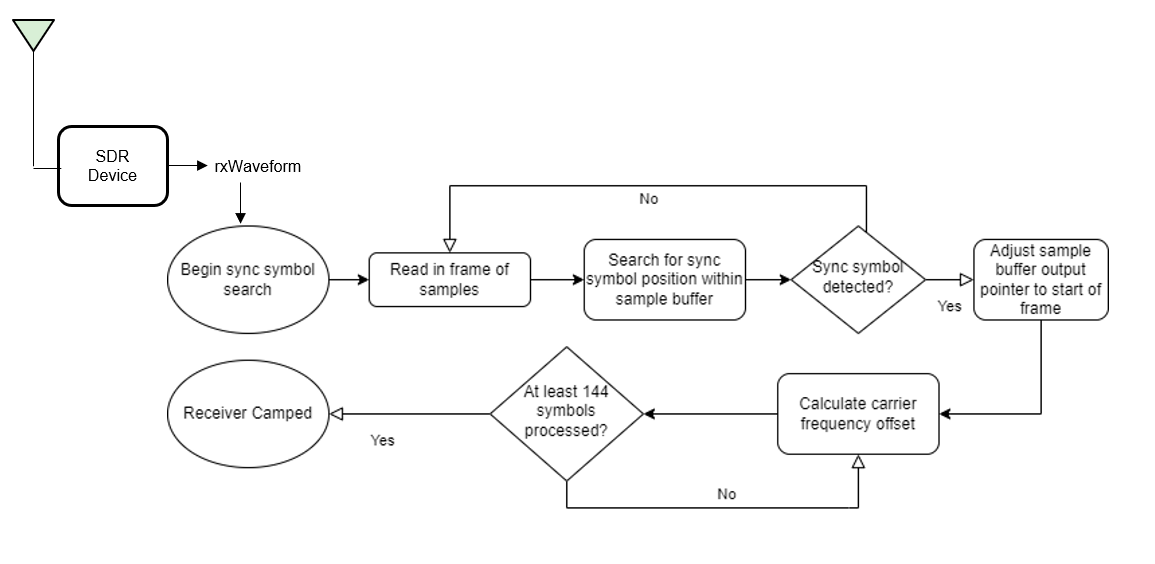

### Receiver Processing

Questo processo è l'inverso di quello che avviene nel trasmettitore.

#### Equalizzazione e stima di canale

Inizialmente, il ricevitore OFDM esegue la stima del canale sui simboli di riferimento demodulati OFDM. Per rimuovere gli effetti del fading variabile nel tempo, il ricevitore seleziona due simboli di riferimento da frame adiacenti per stimare il canale in due diversi punti nel tempo. Il ricevitore quindi interpola linearmente le stime del canale tra i due simboli di riferimento per ottenere le stime del canale per l'intestazione e i simboli di dati. La funzione ofdmEqualize quindi equalizza i simboli di riferimento e i simboli di dati utilizzando le stime del canale.

#### Header Decoding

Il ricevitore estrae e decodifica i simboli di intestazione per ottenere i parametri dei simboli di dati quali lunghezza FFT, schema di modulazione della sottoportante e velocità di codice. Il ricevitore utilizza questi parametri per demodulare e decodificare i simboli di dati.

#### Data Decoding

L'errore di fase comune (CPE) interessa tutte le sottoportanti in egual modo e il ricevitore OFDM utilizza i simboli pilota all'interno dei simboli dati per stimare il CPE. La funzione helperOFDMRx corregge gli errori di fase nei simboli dati e la funzione qamdemod decodifica soft le sottoportanti dati in rapporti di verosimiglianza logaritmica (LLR). Il ricevitore quindi deinterlaccia il flusso di bit demodulato e la funzione vitdec esegue la decodifica di massima verosimiglianza utilizzando l'algoritmo di Viterbi. Il descrambler descramble i bit decodificati e il comm.CRCDetector calcola il controllo di ridondanza ciclica (CRC) e lo confronta con il CRC aggiunto.

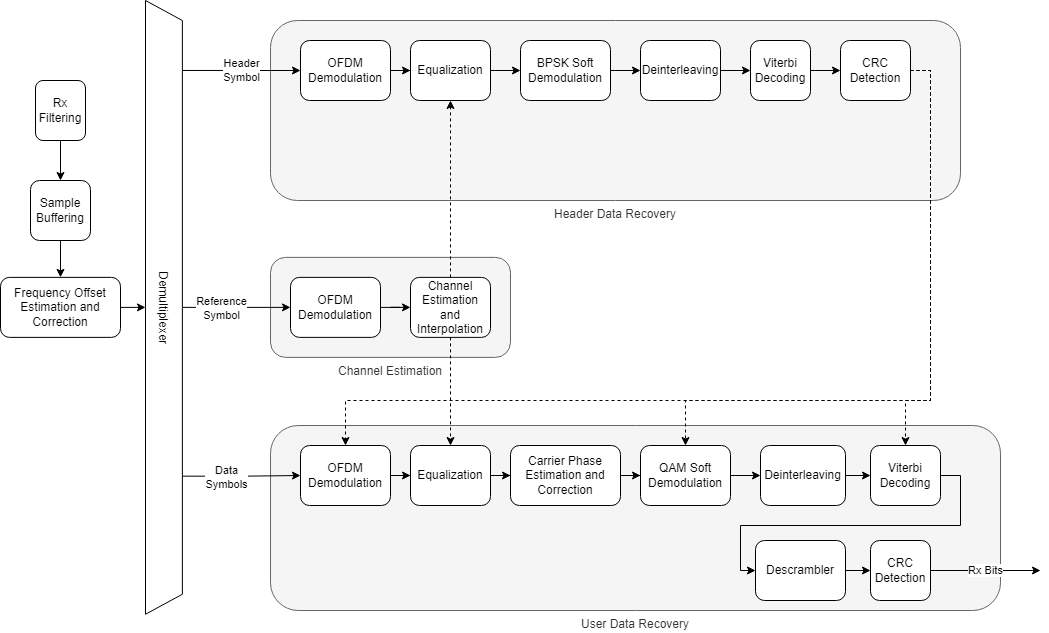

## Establishing connection to hardware. This process can take several seconds.


BER = 0 



Sync symbol found.
Estimating carrier frequency offset ...

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 


.

BER = 5.000000e-01 



Receiver camped.


BER = 5.000000e-01 


Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.489793e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 10: b|□CS`World4)□G□□G'□Wsoxu□u□□□Ok92I1kOl□uSVw`World! HelmG'_□□Ld! Hullo Wc□ld!"□ello"□!`p:TRM□□Lo
N□]V□#
□□;□o World! HelFo"World! HeiOr5u)H+s|`□{2□7□□IBIS□1J1□YUi□□d6WhelmGGpx/P$! HejA+<0□WE[a HeliL<N□□CT! Hello%tsR8[□9"S+{7k9>□□□(□#ell1hWorld4,t0`I□d:aW□KV Hg□tP#,='`0Lp□□□<o5^□<L0□d%kL8\[
□-□"□X]C□eF World-_rSk|o%[□Z□k! Hello Wopld! Hello @+x*vu□Hello!1orl0□ HelledWorld! Hemlo World! Bg?□' World! HeFu
□□orls|□/□IN@□7□>^□ex□|
UGG Krld! Hello Worf)□(]i□>>nh□rld! ^ello World! IM	□□ WowO{e`He9□ J□W?,d! Hello World!
Q
|ljUt□rlfspJ5llo norld! mF|=!iW;MWd! Hp`□o WowQ□□VHellj	
]rld! HdSV[□□G □0□mAX□□)□9)KE>Z#1e8^{H.lgv□! H`□hWorm□	E?\llo WnL□vZw□ello [□rod+<mLQ□□ World  Helf□/9)H+d! HellE96 □kGn□Xello )□%1Xa□W/="}[3orld!DHellEl.ox*\E Hello Wm□cU#q□
□f)2	□ ld,□y'□~□}forld! Hello a.Z□Xb@\Vllb□ @bld! HewVn	
s cGi5D□!-□H5Yd! Hel8mq□□
V□_ HellE3m□%$r(5A7f□2□9□ie3i Hello World! H`MFsa}qRlda#□n

BER = 2.967609e-01 


Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.503423e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 11: belj[`Wn□CCa'a?□l0d	□*u&pa`□-)j/rld!+W%llo World! Helll>#^rld# Heldo Bc□$}□`Hex/qU<□rld! Hello Wo|L□□KFJV□:□ U□M'V HlFZ0"World! Hel□0@Cork5D`Dlo Bc□9hZw□%lop}[-□ld! Hello WorlUj□%i2□V]>DN,N?U:ell;□RMG□d! Hello Wo}□5@:1ello World!En
□□9B,2~□d□&helmRK @□ld!*□ullo World! HdD□□fky□=+$□xeiOsRWorld! Hello World□U:enlWorbd! Hdllo
N□□ld!<{!llo!□□x*\lq(elF|□Gorld! Helu
□Worla!_Ft
□902lN8En□Llo }w2ld!□kK( 0hd"}□d!4Helle World! Hello WnZ &TK,i□Lo Wov,d! Hello @0□□R□Y,lo"□□|C^X □V&+xx□□-$O1 Hello Gorld!5D□□□o World! Hp|lo WowOZ□m□□E6sQGorld! HelldYWorld! Hell6]j□□	□□Wgullo WEaQ□E"Ho?Z( World!^h□□;□&nR□□q-~>ullo Wox)%C□:ell3e4U□	E?I□lo Wm#-LF/@lE9'orld+d □~□mpGt	=*a Hello%ts&□U! ]l>$aZ%dp+mvN□f□lo UER□3kq□6O$E□?□Xt,!!□ello Woy□#V□XSc8v#W`□C /□slo Wo□8Wpn□□llo W□rld!5B%ll:0Wot38□d□□(2□ □\6□Ufa`□1b1 World! H02i□□X□.ld! Hello ]'wG
CB{/!=□thUX*]□;k.□2O Worln□dq?p2□□m□□+q,□	□□SA Be6ld!"□%

BER = 2.899333e-01 


Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.502785e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 12: HelF|(Vx_□ ! B6p-GGBawOv□m□/'□1 0fe$d!elF|□%ow□D'□,elf) □\ >z$	□Ou□o Bf#□)'□#□	4p□□orld! HeFu□:□6=□"□H8Ou□OuG@H□wo5Hm,lo WoZod□%kz1Z
□m□x+snNZello!□orl4! Hello5Z□MW^X&Hg< o!+/rlh`DHello World! H;□□fzK1□W1/□r□*Lo World$□Yelln4gosD□Hello World*(Hello%trjs9,w1d#lo World! Ho□lo World	F□□2Lo World!□1ello Worldk`Hello Wop=~□□*□F=mq□bgvvZnOely`□;I□□'□, .□□o"□;~(□Hp/r□OvGI□ >z□ Hello WorlkE He!.1U%nu<d!t9
□□□ S□~□vZw9ellaUOh0*w("32%8□8Wnd! Hello WorlfuM@8STR)j□□{9□hg□llo World! □V&+G:□ov.□! Hexlo World! HeyNo World! B#|lo Wo]U□*#4CSn□w&orld! Hello World! Hello WoXld!*□UZko World! Hello VWrm[y Helf+^worlf}3f;Llo World'
~"$lo World! Hello Wm#,a! Hello World!□IL7J□")□&.d0os4!i□ Wm#)□!9(□llo7V.<ld! Hf□□□2 JR□□`o&/=v□RWorld! Hello Woy D! HelFw`Wn□ld! Hello World□9 +Llo World! Hello World! H`eo'6Ed{j[1 He8_+~"□d3 /Fulo World! Hello%w□r□*□□□%llo*E@H*X+hHello WogJ□S[□r1Z□□m□rlL! Hello!}v□ld! He

BER = 2.753784e-01 


Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.544239e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 13: Heya&"□!`□ ! Hp`J□^#\8+fpa`ello World! Hello S.Z□l6el8z,&orld!t{!2,o Wgrld! Hello WnZ□/O~i□y|P□D@bld$□Vo!6j□`@H□□E bdl□x□(U□□^Ta5
□eo WoXw,7nZ□>P`H0□rld! bey`□tr□□□Mz?Hello Wz~□□□k&-\Q□#K;□c□! H1W%World! Hello World! HJ\SU9World!,!cTlo World3[□-llo World! I□UTo WorlN8DFEllo RG □2a^bE□□\q□G□Hh_^Z4$yLj9UX7IcU:jQ□□ WnZ□-□K□c|lo WJQ□□S□□□□E{□□6x□UM□{□;□R□ □□□FhbVlo
□□qp}E He2□U□LL9□;E HHW@J 1e□ld! g□CV□ K□rld! Hello @2M1q>hHeopo Wor`e	G]{2Lo ])O□d! He`□",'EKn5n%k□llo"
 □2E	B|w□;'G^R□u□! Hef*□ Wor{4□@□)□i□`World! Iwo d□W□J□T{!2□o World! Hello WoA(9!`lc□□□_□st{!llo Wj[Q□E Hello World! Hellm[3orld! Hello World! Hellefm□□:ng□Q□□lo%tfZ$q-R□□llE<q□&_6! Hello World-^<V(□' WowNQ_T□iHn`□WEj,d! IL6s2.worle	GekiV□RWorld! Hella WosFWE Ho*\/ World! Henlo□m□rld! HJVM^;^orlN8IgUlln□)□C|e!.Hel8H0Wormt! Hef*N	
qR5□P7□X□lo Wotld! HemE5BworldQ Helyc□}@H*]□U:o+|;□9□A=□! HeiLo V^MP$! HejSU93cf]r2□□U

BER = 2.789378e-01 


Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.524034e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 14: Ho*T/ Wo/`$! HeFp/ Wm□ld! Hello Worla□<6Ello World!
Q+llmZ,>□□^IaHeln=td><u !"*{~_□	3oZ□q:□`□llo WzGV"□*V□8_2□□orm+Q HelllhWorld! Hello
N
T
□□□=□%lj□c.□ld! HellefjP-|d!#Tw1Ostnm#"w? HejX] World! He_y□G JTBT□K321□□r□\d8\Hel)`U?;9□@H1_□FnxU□□c6}□/=#@0Worm_v\	□eQ□DWk, d! Hell:.w1□□d! Hello World! Hello World! Hello World! Hello VG□LfpnXOllo4d1Rld! Hello i(e1Xm^heFu□
□%#v ba`f1T□ Vld! Hello5[□□ld!
Q□u>v\wo#,s|□□{L□□□sR□□a	5D□?Y+ Wop8q:□□#T&)□})Jk.d4{)f+□□□□rld ello Wwr□□o%k□="} WormAa Hello World! Hello5World! HelmRK3ovld! Hello V;□bd! HeliL)World! Hello World!*□_□ AZ.iKn5o
{□llm□m□e1_TRHello Worlq- J□;B) Wox(□E Hello Worle	E?Io Warld! Hellj□^Orld!.MGX_$□World"0HellW%tf*+fpnpJ□□@□)□rld! Hello Worlg=b*Q□Lo World! Hell;Z.orldj@39y`□ World!
Q□o World! Hello WorlN8□□Ull0□8*Z3^helmS□ @bC□□)u□llotd+,□Gi5D□a□^7□p#□D□□QZW;' World! Hello BI□e3S@Hello WnO□ ! Hello ])J□ ('_8□□j□Karld! He

BER = 2.747221e-01 


Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.501838e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 15: Ho?XG2K1□□oN0Hello World! Y~o□>k9>1□5oyIm|lo World!
P%lle[H162□(&qello World+`r}eSo Wo {□□0~ello World! J1□`□792MV"□`Helli World! Hello WoX□G? Hello R`H□□!( .□?□m□=w4zV4DelmGG
m#(
|□(□u□Y Worn ~}D□KhWop9M{ Hello WoXu
	□□U2□□w□Y5`□T;D□{1U@0fO□:\6hello Wor_/q HdLlo World!5D□{1QU*□ □3i□(ello World! Hello World! Held$HWor□D! Hellz□> bld! Hello World! Helln□9.Z□@! Hel_C □\#"cV□T1□]o*□W:ld! Hello WouiG=/r□os2,-□rld!0J□llotd□&^□vPHello Woe1Xa Hello
#\#r$! Hello Worldu□*ello Wm!X]□K5□Fu
_,g	;□q)u$E6q World! Hello X□:ld! Hel9t□□□wOy8eln;O□orjJ! helpo World! Hello Wm#,d! Hi8_/*□W:&□E Hello World!
Q□Fu□>world! HelyJ□□y~□d! He&*o W1□□Ng□	Xo%ts"ld! HellE<□oryhY Helllc□/rFrg□Q 82□ World! H`Lh□W□En,d! Ho□lo WoriG) Hello WoXu□F#
4"□□!j□/□2! Helm□H0yu□□#q□0`IGG^PNf"□
□_Zk□□f□rld! gUli□□Goe4{} Helg 0World$T59□	cO2I□!$! MT!-□`World! □r0e^+Wms"G?□;/!674%Vx□U:ello Wog`;i Hello Wm#$WS$Helln□?□rld! He

BER = 2.723881e-01 


Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.495945e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 16: Hey`□hW;A>6$□%M□Opd	□*s94□Vello World! fEllw!□+'`:T]t%llo World"?□i□vq WorlgE.G_
□j\□□Cl0□j□7□Lo Wm	o□uM{ OpJWss0= a He	JS`Worle	G□i□lo World! Hello!y1	=□V□□□llo World! H}`□\d□G□y□□DHello World! Hel$□□5E4Pd! Hello ]+cV□? Ielj_+8I5{□'□&□qy7a0l	8	2<□□c Worg
□□s□;C□ World!7□_□lo5[}2ld! Hello WoRlq-T{Q^?_ World! Heye□ World! IY4lo Wz^f"□□MMmTotdorld! Hello |□□4zTxHelles□□,Ld!*□]&*U Wox=*□ Hello7□orld! HpEjP□u<FUhJ[J4"SU[□orld! HeliO WnMVD! Hello VRcS H□llo WEjS^□&Hello"□gg`□□~hello WotP'M Hello Worl□!5D□u□o World! H□l-oBb□W□I□5S4vM N□orld! Hell;5X□8*Xa Hello World! {4$□o World! Helln□<□□□r&))e`v□□Woqpd+ K4"FZxBc3DzT;□□o World! IOLlo World! O□llo World+`Hello World! Helyv
N□MV□! J(ePo World! Hello Wor`□0DHello World! He=□K~7□/wt! Helnw`World! B!□lo Wopld□m□□eQ
]??sD□
O1F□8V□□orle	[K□>>p@□or=□! HO □o e□%□9□w□UUlo World! HeM□'9*□\□0H&qelyc^oorld! ML7s/ Wnr□s! Hei□xx\□□□$! Hello Wovldu□□e

BER = 2.690877e-01 


Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.477266e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 17: Hello World!
POZ*P□bv	,d8]!e8ll?□`□*d4;U□llo Wor□d$□□k$_-q□□-□.gello WorlDu He
□□□9"□VNz_a8yyt□□`bld$□T@[T4"%□&8Wj□y□g?CR,8	>0a Helz25trid□pn[+llo*□U□ld8BgB{1_"□0:ld4,lmllo Xm#(1! Hee6□#92Mdt! HeyX.3i(c# ! Hellifk.d! HelY□TKEk□Gj(Hello",l	?R! H^□,o □\8!5D]?8V□o World! Hello7
fO□□C
QYI□' Wos□KO HejS□ World□`Ho*T□□<□d! □C(2□R□m	;d! HO □o S□2A%V□(1_;□+Wog`xHello WowOz! HemDo WEk□d! HdDlo Wj□ld! □i□v□ World! □~llo'j□%$}vhHelli' JC|□i HemS' WowQ5DVO□P,o World!"□
□□8hHU□□D! Hello □\8!2C
□_□□□ World! b|	5L<□□Cld! Hpk□xxH3W□K$□T@□Gq World! HdD□g World! HpFto Wz#)□U□u□llo World!"32$lo WG □3□0g□□vNDWoqq}"#34"!\□}Y□□Nm`Hello e3%	E>`O$z, A"ld!!`l@□-3rld+`H1o(0\□VbF□□ HelUc □\6 □Zw eln>n□><□P□□#8□E	□m□)O,!, 	o World! h□
D# R□2)□-R33?rO World6}t%o Wod!t{7□□□,(□rld! FEll:.WorlzA Helm□ WorlZ! Hef?ZW{Q□□U?□Ulo Wog`ng□ ello WorlfZtx/!=
Wj□Bld! Helli□mw□ld! Hellmt:R□!j□t{/*S□ World!#Ve

BER = 2.740553e-01 


Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.434910e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 18: Hello Wo$□H#q□□□325]<F□t□9?JV□o WosD□(z(ello We4T□i
Q□C\o□wosld;u_□= Kc ?Rlq-!f$$LX□~□d! Heh2□^}EKD~9 Hello WorlT□@6□_X\hWop□]IGAa□
Ra□%4SfpnN\□lo Wo&\d! Hello RE`p□4)Hello Worf K Hello World! Helo3	□orld! Hello#*□Rld!!aJV□□□J□rld! HelleeworldA$□r1|□ WormP□]!fv□o World!5Hello Wd□-□O~heiO□}6
wOx□!6□OpZd□cr{BMYHfKlOG+□Zjfb□?K□s2&4□.□\l)u□+n>;WnQp@+fXelCUKH□2m.□f□ZVu□[□\9]se Hef?[□YjQoz□ bwg□'5[□zld! Hello9□%#"t□elkWorld! Hello World! Hec-GG^5n3940/□□|E95?rld! ==,lo Worle□K4$#□% Woro,! HemD□w□orx□jN□Sh□o5World! □w□\P□N#}□□! p(|□□□7orld□@6□HyK$X□6//C□r□□:hWu[0□vZ"□Sf+□*□trld6[0-□Fwt□?'`?□1%
□Du□])Hu□/ dell}9j□/`t1□J5]wf□?$	□0□d□□(2□RQVrld! He8_+bc#BS^
□(dD□Lc9(p□3□[□J|o□ Worlm□3m++n:n□"Q□6t"□
□L;□□Vrld!/hello World! Hello Wox*^□232□□x"%j
:q/□r□lloj□.hea`] +Llo Bk□Q
f=FEllo World4RHelmR□3c	;,! HEi&Y{□□&_□IGA`V□□□bld! B!8Uo World□8□%llo□
P{Q_Y7□Y-lo World! Hello World! Her□7>"□#ld! He

BER = 2.782541e-01 


Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.437336e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 19: D□*Z(hWorld! He`LmqM□wOa□ ]i□wLa□ □□?"<6Ello World! IM□eR^world$Wf4"wo Woq□x□V$oL#UYH8]Sq:□□#□yt)Q[d!u□P□A^:OJQpK□U:`;1RI□□#□d! HelB%BVPblh_T/F$lo World! R□{m!,%orle	mt%llo WorlWa*□\E6□w□orld! Ho*□□R,8□ld!D]~O'□ World! {78_+□{orld! HellB□Worlng□□o□;G Worlfpn[P□jU95N□`□U□□$Q□□@)□pC_pD^□□□\h□orld! Hello World! H;□□□ World! □V><P□N□~Ld! Hello □L9□;|.heliL%q□2l0□hHellz□World_T{%llg<Worn4! HdD□z;t/rld! g	llo d'rld!*QejAi□9□qB;Nhb|□□g WnZ□3a
Q□2Lo Worlfpk&81a.]?hzAbya|\Q□8□Gorld! □V&!9@	□ i□! Hello World+fu
□|o World!
Q□V!-q□c}□"□gA=llo Wo@?Q\H32C□□LX□□□
□~hellj R□W□_suS(vL□Td><!□E"□%llo World! Helf+hWorlfpoJ□;$o Woq□g7@6□]wl[□□□:npE>`4s□,(6[k,! HelycTd□rldu□□ello World! HellWE A*t%□9*Y□,o Wosn4!"□+ulo World#qZr1Pz,/oXt$! □!f*V	W□,.K□□rOA□o Woro,! Hels7
N
Rld!t{□Llo Q□rld!"□dD□;#D_G□2C □□□iE□□□XvKa Hde□".□	@! O□Lho World! B#Llo%tqwO□ZhHello World$Pb|	JS`World4,:6XG@0VR□8gjnb]'□□]?□'bK□U:e

BER = 2.809940e-01 


Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.431088e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 20: Hello World4,<V="□RQPL□□□□w_\lo Worldu□6Ello :u□JYAX□eRJH2g|<lello Wc□~x+fp1,lo World!%kxllo ](bld! H`On>n}/□:w□□6DyJSdX□4V}W Hg8□
□x
Q-□□I'p-#=td+□;9□□□_□="q2□]|d! Hello Worl]! Hello#Kordgks|1n□o World!%hr□lid}□}□□F)□S*SU95j[□<>□S1_>4(Wop=*3[□OZ*}%tsW□cS+&;Hlo WjPL□U□□V$lo World! {'□;@0]*J'
U5Hello□□orld/I□lo World! Hello World!!`□dlotfu□X'=□□Ello#.A=|b□"6□□lo Wo]□,! Hef-o E□q□5e Hello",8:ld! Hello8])KE+W~>wu□IN□]Dny□□k-y`K World! HelLo W|A,f! Hello WosD□□□1□llo WVO□d! H``□o World! Hell□□□7"@D! Hello RLm(ng□□□6u
□□orlfpo~tk$
WBzQpK□_]G)4q□X□4{@! Hello World!!`(S1_~",m19\HHey`□;$Krld! Hello Worlfr□Hel\o World! Hell0□\2D6}t%llo World! Heln>n}Yrle□<hello World! Hello□WotU□! _8P,o World! Hello WorJ□O□&-llo World! HellJ□d+&_4! Hello□Wov□d![□c(2□xH2k;,! Hello P□rle□<CUllo"□$□3j□□2ME% @bld! Hello WobJ#|□□"}	0ybld! B6XUo World! □□□w[G□Ekb5o':ello Wog`%□□}*|lo Wo\w5E!f□C.o U:L□:□□□U

BER = 2.797714e-01 


Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.441930e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 21: b}&=□ W;Cj#1 Helv□□A}\□N□H-Cllo WosD□
OX□{□□I}v□□mpxHello□M	62□Z Hel`□ WorlK□YHenC□j□!8l0□j□
□yt□H1wOx□□\%llo WjQqWXBb|□□g World! Hello World! Hello BcRld! I□□>cR,2□□D!&□/='□~}PHu>=a`□llo WosFS□ Heylo RLc$d! Hpi□@0d>d=t{$□$o 9jQq>2tp9-#+td□rlb□`HelmG%try\d! J5nlo WcWLd!"□+3$p}Ba`□3i:7g□[@0Worl$□□1ellj\□Ej!pF7□!□lo World! Hpllo 	□□Ld! HAllo QU8*\`□Xelln,I1□□□:st□Vu□<□orld! HemC□
□[K□□□□Hlllo World! Hellz,□UYJw_8P,o BI□□□{@6□8Po Wn[4si Hr4lo WopS^=a`□(9cQE□rld! Hdvp1WxU□□:TP□V$FN@])R8Wa Hef,m^"□aO□j[□□~iGRWorld! IM□IK9□□Xtd6R$elm □"zQpBIW□_□□□□World! Hel=
q□:T.Dp((9o Wor{x`□□ell6+-1X`□	M□OqQGormGJ)u□;B7 Worl:□ H1_(□.Gorld! Helox}k/rld! z`□A.DWorld!5D□_(□□Wog`□60Hello
N□□Ld! Hello □
□,d! Hello T'rle□□Q%llxxKz~□}S Hello WosFD! Hen='5[□e2D! □V:lo Wor,d!.□F$@agGS
yhL;:ello WnZ□<m[K□<)K□□orld! HemDo!□Ea~x□E:`Hc B,8:ld! □□o World!:O□l_=#Gor`?"LHelF/ World! Hi□:□□gPH
N□g_□□{2□□orld!5D\

BER = 2.813195e-01 


Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.460051e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 22: bv□33`}vMV□i Hp`□r5BtPCa□□□yllo WnRlduelA_□14I?T□GAX□o□ □\7□K1 H`Oqc Worl~_U□y^iFzK;Cld! Hb□Lo World! HellE8□orld$b32A-!2World! Heleo Wi/Y□□ Hello!dld! J1_>;□](`le	GAX□	e[#orld! HelljWx□A□d! Q_□lo World! Hello Worr□K2M□E6s~"orlN8 Helln
d□rl6( HeFto%tsT□&pey□agWbN,d! Hello5[□rld!□n□□;';World□N□QUbE WosD)a Hell\Eq□|Fd! □V$lo ]<vV□U□wZdlo World! HelldN%33Sm□`□□□_Ih□orlq□□	*□&'
□2H□□_U8□$lo World!&'□L8\j□8/V"□□34"GfrWoryhc□□+~lo World! Hello Worf"□I!=lln□.□jk9□'XfpI□ Gog`□
□□□1P./BtCv□`hHiItE WornD! Hello World!,9kMD□^woXu
ogZ□u□$wx□sl□□□r|	J□□X□□□$□ Helm□ VG□@□Zw34(9o BI□□5o3VEllo W□rld! IXo World! HellF□LL9□9QG?Frlo }!>□ng□□□5@A~q□A□,! HellE92lN>1(sk□K□9"□L1-^heF□g%tjQ_T□l>rj□q□rld! MMllo!d□2ld! Hello WormLC J5iNN	j□□]U□'?Fp8K Wo{n□! Hello Wo~ld□9*l□?[□`Orld! HVp8V□□op=□HRHej`World! Hef1.5OL2C?"[□_□l;□,;I(d! Hel8o Wm#"□JDD□□_=z"□BFRlz3^y@,8/J%	Gn6XUGBWo~□LBh]i□FYrQ^□ld! He

BER = 2.828248e-01 


Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.440711e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 23: Hd□Cf }vO(r&W`□}	□K/"d! ]iI#,7l□
□uEt{1□vG□g*!C @el8;
□x62□VQ_=llj□Ie5},□F□;
So We4~d□ [□|lhjN
%1j□□0ello!j□PpI. MF□?@hWorld!%kr1S25G2i4q-QWuLyILBd%@j8B~'□n;□□.Zld!.H□O'□~wz~J>=au□8lotd+,□□! Hello Wos&*g□?^□Lo WoR8[□^h □C□X□Crld oXello Worle1 Hello%tsVld! J□:n>n□}rld! Hello W□d`□v[□M□v□ P□lL1(/Xello WEk	<8Bg_□m$N	Elf(Z[Kmllz,rKg□I`]!C'□1*□[x□Gi Hell5n|C^_0Helll'□orld! Hem)□MwD□U□Xello"□uR□~8RHg□;RK3orld! Hello World4:MFpSo7
S:ld! Hello World!&(□llo U;Kn5:}Xello Worl0!□ v=(□#KI,LfuH]i□□o World! b}"|o Wn[ld! Hello _o|ld\N□ckto Y@H□d! Hello;]orhe□~hello World!*Z4)bA Wj[Q□E HJ□VDYWorld! HellmpWormF□Wf;L□1□gwH□@6□O□o World! Blo Wz{;,!#□$□□G95s3D□.)Hello We4{□□0Hellm World! Hello Bc
Q□!7□vLlo Worle□K□-llo %W;q Hello+,}□V
	□□□@`Vg i□□□Q O&□Y~5n8Wpn□'□Xvq'4□ld! .□llo WnZ□□! Hello Wor8Lfa`□|SC□sR6ld!,6□□FvB,8:ld!%kyFu□	Tgru□□gdello World!□Nellefw;A?x! Hello □\6$Qy?□emSU92` □du□□e

BER = 2.837409e-01 


Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.416413e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 24: Hello Worl□! Hello World! Hellj□K□%$d! FDD□L<sorld!□heb□o
N
]□;1 HepJ□ Bc ?Qe]"Y-□@BxU□ld! Hel;r□M□~2□! Hello WorleE Hello World! Hello Worl;pn□-Xlo World! Hello R@□ld4)□6XLo World! Hello Worldj`HelY□□□lr□d! Hen□□ World! HOu	;L)orld! HellehWorld! Hello World!!`□J□o World! H:iJS`Worle□~>□llo
Norld! Hello Worldlw□*$do□<□]□c6Wletlo World! Hello WOx*~3>Helloa2□Hp□V□yuFp)0WormLo Kallo WEk□:□ He8cUU%>bF}Cq p`2□^□c□□YJello&hUX*\h"□+|8□7
U□ld! HeiLz!uN=Q□□□	Z\lo U?rld! Hello World! Hello World! HelUo World! Hen□o World! H`c^world nz`□v□Tf>PX%y I(D□g }v( @! Hello World! HO!bo WCVld! Hell!orlg?+xello Wz}□"□ello!j□□ld! He3*dN	Orld! Hc|lo Wz~□d! I.	,.orld(:zdD□L=<□riG= Hellz□ A,Ld! Hello Wotld! HemSf□<□□O.g8□21P.nworld! He9wL<□jQtp/pu□o World! Hello World! Hello WorlE□Amf□=u,)OriG<0Hello WowOx□ HemwM O{A□□a□□&$o!2,:~□0□j□%iO} World!!8ellE92Q□Pkv[□1J2P",8*ld! Hello □i6+d! Hello*□'^FRf7□


BER = 2.792209e-01 


Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.439512e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 25: b|i-□ WogJD! Hello World! Hef*V	
Y-1hP.hello Worle	RHello VG□`□$□Q`E4s`Wo{Q%\H/pwOqV	Oru□	E?Jy(a^#,`Rv&□T@□C□rWnfld#□□l6p/ WoriG(□r□S/hd	□□□□□k3□llo Wj~□d! Hey`□□	I□ld! □-llo FU)1[4aHeJ37 Worlsa Hel+Wm<□~=*3%kxllo Wojs5D]!M!:□khU?;□□□□Y-	□□K16□m□d□pJ□5%tsW□KV□hello World! Hello Worlng□hello Worl□\□HemD
 WEk□□:b□f□: <worim□K□K3,z,r^rld! Hello W`gu□! Hell:cK1□ld! Hello Worlf□`K!US~]Y@M0j□ b|□p,YTp:ld! □|□□□ Nm#"cS&Hello Woryiu□□;□□mfcW[□□□K-~@3@}tfZ□$!USF□□o Wj[D□47□Y,lo WnZ□.g Helf□'Bg□□!u□□!□	j□rld! Hello WoKld! Hel8\a□orld! He8]z□KGx*]'□Xello WoroQo*□?□lo P□rld□USSLlO".o}n5o3VEllo"□+-1X!o □Fu
□3oqqj□DH□w$|Aj□□n5euD□llo W;A=Q:□r□|lo World!!`ello WorD□,o*VtDWorld! □V(□□ Wm#vxuMjJ□□@□)} s9□[□etl\[□ e1Xcq□i□Lo Worf(Z Hel□j□hUYdRf0bvC~i□mE4Td! Hello World! Ht□lo"T□□(o:ello WorloM HelmF Wor9p! J□3$k X.O	Gi5D@□□_□<□-□d! K□w;□9 @b_K1□ ello Worla□G:ello Worlk□HNZVRhW,+□□□fa`□u□j□I4\(□L.gU

BER = 2.812004e-01 


Detected and processing frame 26
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.457764e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 26: HelFp`[ormS□0Hp`□205[AzcV□A*V□o*□□Y□□Y5Hellefmv□! *□Q
□o□RWor8Wat{+□H□]>Ek□WE HekVvEfFrld! He□,GEtmRld.D□QVy.D92N,e	@□f□P}w3Sui Hg=$/ Wz~□}DWfEllo World! J□?hR□□C^X□]~XU
xWorf Hk0elln	
□5{□a HelR□U<□]/□_cV2}%*□]o
□nO□NX)]X7rld/mjn□3□:Korld! Hello :a]W
□□?8S□o Wn□`d! Hello5^□2ld! Hello ^□&□k□ Hello Woryh□□r|llo Worf$%/&?7\P□□□ ld! He8,o!xorn5oj□ell;□□1□ld! He`+o Worlf□ Hello Wcrld! Ha9`□7
U□ld! □V
Y(□□□rld!!qell@□;osD□□b92%@□ World! Helf)□ahd□□34 n>k,>[Q□Og?@D□f□<l:p;|/□kCV)xBtFV□S Hell7 World!5Ai□po Worl$!*Hqllo WorloYh_8P,o World! Hello WorF)o □V(□8}k=n,d□9.SP,o WotS^□□f%llo Wkrlgi□(ello Worlfp;J4v□s□
u?6d) Hello Worb$! Hello World! HY-)hL2ld+fwsk□O%)□riG2>q□lm□o9<F_□! J4 .□wy0 □□□□&;□i@□@□riG=I>eF!5$7oRlLG HOu□ktd'd□□P5D□Hwf□<□y□}! HbFu□] @bla!tn&llo~7;,□%\IHello W_□	□Q Helg□B})J$sW Heo|nW□ H□AW'Aallo Wor□:k{□-□1RK*□S"E□□jE8_>g%□r□b nb}-S`",8/`□□□	M
□GB□8NX□!Wry={□□dln.0□□|J

BER = 2.837596e-01 


Detected and processing frame 27
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.460761e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 27: Hello W;A>e	mxZVu
□9}	0t! [S-D
□}rld! Hello WorG]_T$eC□"KgER8W□Wf8S]o Worl"32,l:;g□e,d! Hello □td$CHa□g□□(Pq□□i Hen= □,8	>18 Hello Worqb□□<#W□=uLOrld+fpellnoBOrl0□d□kVZhV□z~□sV□`□f*Y+,+,□□~}D□□hWo~□ng □Tllmq□BUs5MtaLD!\O9@□ □Uc-□_?t+□!`le□GAXo WoseX□tmF □o95NF d5 i+k□O□%hbF}D□<	□□mq□;bl|i□□□cn>ij.□□M,w□□□O□ Worlng0□f<o7,]<G□K1 Hello Wkx(
$c(elCU\WorloOq)elxo Wor8U! Hello Woy□4u□□(<CUW{Orld! Hpl}x□9)Nld! Hello BI□□BI2g_□□A2,8/e4! Hello World! Hef)IH%j{Q□Oj□Y,lo Se4V□! Hello Worli! He8_/ T%?=d! Hello World! 
#QP/ WortfYit^□:□k8□rld! Hello World! Hp`□mq□wrld! Heo□o Bf%|□E Hello ZPx`%	G□%llo World! HellouLL9 kE H1Y□o W;A?{|;J6+;' World! Hello U'l□

JT%llo B□3#
n0□~J□^ World! B(4lE9 □rld!"□%llo Worlf□□7-llo World! HemQ□@Wox-d! Hellou[□□ld! B#Plo□m□rld!tz`NXR□□orld! Hell; Wop=□a B#□□<□World!4□elycSKaRld!5D□|FvBxVbld! Hellmq□m#"LldHelycdWEo□73??FpJV.World! Heik□
N□n`□rnb.\SU3rKJld!,/l

BER = 2.838291e-01 


Detected and processing frame 28
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.481740e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 28: b|Q□□hWorlb□0H□□NZRWorld!+'u\lo WFq□5n□□ello World! Hell0}[□0jwO□eellj d'_ID! bO>iL:O \*nO□□S□;C□N
]V□$□TE8_□x□"~□d! Ho?rNnw;Cl6□<□□k VQ]Ufpn[_□k□ World! Hey`□sg□]|d! HVl!>m G□@BV Hello World-FqbO Wor;]a%kmllo World!*□□llo World!!□z1`□□World!#W8`2□ □]	;□!!mi□\o World! Ho*|0oBFtj&Q□L8\j□WXu
□ Hello World'□r|Q□□ World! Hello VX□eY=~=□□,o!□O&_□u□Xello World!xHelm	 World! HemQ□DWe2leA b|□s2;{Orld! I~O'□.worlsp□_8P-P*N□DjvzhHeliK Wop(d! HcT$o%tsM□ M□(□vLo World! Hello World! Hello World! ]iLlo Worl□jN□(=□o World!
Q□1P/ World!%□□u□@□(□rld!#x1]ujd=/rld! Hello World! □8VL□ World! Hello"□□rld! Helf)□/z~2□! He,_%l[□□□+E Hek□2.Gorld! HeiOx}kmn2□\H8ello _orn0L□Hello WogJ□P5kyJ□□ World! He="j□L[H$k@□#3□□□t□orld! Hello WormN□DHello Woy□5o232&+g V
□Z#1
Q□0lo World! He@J'□~;KQ □Wrell;□.^e1Xa Hello>world! Hen+□ Wo]ld! Hello",8:ld! Hello ]- i b(He8lo World! Hello WnZ□t4,:6Y:hRWor>{f`Hello!{FRf7□]

BER = 2.818689e-01 


Detected and processing frame 29
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.484068e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 29: HellHhWorld!
Qg=<o*O%;n\□k&:V□o W@H□□vN□EyJ
□?□rlng Hei□□l	□□□□DWUt"^}uLL=□□_
~□;1Y!hori
H□%U3□'9+3&□U2□□_u□7>"□□ld! ML6p-LX□4|g(
HE□□W WnM]|6R□PO|o Wo[ct□□]Ello V□rld! Hello World! HeiD
W~P{aRa HelCUYB□&/~3%?K3-GE<H□V□Vv ello!□orld□Y-S□@We4VQL _K□G? WoXtoYg_□J
P)hV
ld! Hello5[□nXXHeiO□Wwor□□□9u\cn□ WorlNg□H1_>0fO□$! Hello Wor+s|□□□llo Worl□U`Heli□□□orld/ello WoXt<n□w_G□□
□[K□d! HHQ□□ W;rld!□Hem\P
□%#"vZv□□8^□wx□ryhZBMFp7g We6□9/□r□llo
N
X~a□H]iU6sb□Y*FRxN□vB3.	□:|H0□o(K2□abq:{.□(h]i□kLk9>9□t+sy{□lo World! Hb□IK9Y□rld""}j□!cQWorld!5Xell;□C□|F}Qt%!□□mq□}#$d! He□$o Wn=n5z3=□o =orld!^6□F□hQ □##UF)J□o□(aq-uq□u□p"~f\fG/□(	r□□bAP#QMOD.2□<@□f+□□N
□~□"d5
y`□ WoriG?%?J|_/ Woru
□ Hj□z@□□2JSmwfqmQ□□+□7~□□.Wo-ll0d7oXtf□gHem6□□Jzhr5`
_u8/sOG\!>-□a5□/lo Wor8□□d□CPJ'□j/rld!'□\Q□|□□$□3^Az□□2L9□\□,M+1 HellE95L	n□! MC□C□nxW/pi'□□
□lo ](□J7(rC{Llo&oOrlN,o?M□=$N
l□O+5□qX=!Pmm□M0hS'_=-D"□QPGbK□□□e

BER = 2.864560e-01 


Detected and processing frame 30
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.489589e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 30: b}l`\hW;M|\a B#@FOt:9J$d! J5ll□7□v	1hP1□"{□GRK.Z□36}t%llW□m□rld! Helg□	□□V`□UN□v]JSamv□ld! IK=v%fdHb8[□*ipOpJWx
Dh$!□W$FZ7 Worl0□
M□Vu□5Px□+a□Ks78lo*□UE□N8B~Zn=.□E;□F%	GI□VZo Worf"□□`el`□w□orn□iRMFev"E[□k
	/ □AbLx}8
}\Wv□Wq-D□U$□□la□□XelFvRK3p=,`DB#CV□@Corl□Yh|lo Woq,d!5D□{1[LX□rld!,hellz□norl}S HOu□e`World! Hello World! Hello □\<v)JD{ □B0}?M□XYV□Xello @□bF|`	NZVu□\□x/Q□! HelmP□D[K□*u□Xfq`□"□`liD= □\o\□,&aKE<□9-C□e2□"7n8YI Hen>h7
S'i'X" □□□o ]<G□□□8:□o.>k,=#{9□
Wi□□8□□Q□□.eU]~C\EG	□	;□□DHem□□ World!5D□w>o RLnld!
Q□-E□u□□,Ld40z`Oq□<_orld! He`□lU)□&,d! He{□□ [□	1□srHO^bo WosDd! bzVp-U<>□□ !t X□;□
/zN□u:#37□□.k91Quf! Hello Wo`J□! Hpa%P□□□3□,! H`Op;HWoy□:U□UX□□□2D! Hello%ts"+t□1SHw.□wP□Vld!)n"e!cY[Vrld&}w_=v□#g□rmdC&M=pJ) Wor
 f0bvC~o World! Hf□URd□|FS_ZwlX□□j□Jq8?QV□H]y`I@□e4Q□□PHeiS20WosO{□*}□□#Lk90□`0@ Hglln`w;SD$□PB#CV□R](□J5DK□□U□C□}@H□□"YD□{1S`WobJ%	Gn6O$o Cu- ;U}\YmdvBe□/he□□K_

BER = 2.906138e-01 


Detected and processing frame 31
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.462534e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 31: b||8□Eq□□□X! HelmGGBaW□□S,1X(lo*□UF_5of]tD□]Ba!`□3nA,elmD□&x-W5A HcP/s*□@H□-.Gbo□□V□<2G□0□hcn=v□"}(□V□□N&;Lj>yU><D +l6□□□9□□q□Y1b<□□□J□^#:~□d! ]Fllo U>n,N3fZ□1`□j□U□□□ZXW:□+xYSorld$QSF.X@DWo&T□+fpvg□p}_1□□d! □V□zj□nBM""□□□
\SU□,.□-□)G?@Hm□h□Or<o#tB#VFvK □FUfpmw_Xlo WjN,d!"□+Fp□q3{rld! T%llo □□Hu□□:Xello!□"□:nlq-□□□V□~F(Fi□□dC
□□A/Sd! Hg□□□E(□rld! `z$l0z|Cm□DB#□v□ VG□dd□DD□+#□
□[K□OOm□□Q□□"y□□□□uH/□="0d0'rld! Hello WEj9hUXHen=' Wougd! Helog%□]□□'? HE+{2□m	□yh□□_□?XV□□orl1:□,ello World!!u□□m□~"□wO□>}R&r□□I{N□ld!D□S60.□3orleS+&4"~o World!!□EliJ
xU	?□□pHep□o □]	<□□MwZs`o&hU`ld! Hello W`ru□H"(ello ]<m,e□□□uv□□ Bld□ u□3f(□t)WV□Fd! Hd;□2)□g7OxuMM@□A□]*□%1hY4□Elln2□[&*Xa5kyJ□□ Wz{;,! H`O o Rg□□a□□~"z|\Z5Z0□3□~g□llP□}□rld! Heq>"□□wGE Hells`Wop<d! □~@C□~woqpB|□	,"~□w2[KQ
lxm□C|\ZW;C=+(□ p`□20WowOyJDHO~k
□Kahi□>}]jmFvBxU□4d! Hel;□BzwT□q-Jk□+{2Ij.□□□"hHn□1F{{nI□□i Hello WiH□Bfa`□k{2□□n□□□|□#f

BER = 2.953968e-01 


Detected and processing frame 32
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.482686e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 32: Heyp□%}"$xx4)□-|lo Wm#";eMEJV□l<□',□^8BHdD□L<t.O□3i Helg□haorld"?□i□wC World!"□+UJX□9iJpng□321□□,])□FEl:$`Ov@O,+&T□P MNvp□LX8□2Dw0{□='□[ %8'l! IZwUi_o7g{9□□□USV"□t□rl:Tello
{orf I Hello~7o&_,□ H1_□p}^=u□d! Hg□;BdWoY\[□_Aello ZU>□d! Hell; Wop=*□$@c|_^E AnZw&8SnY}j□*,`" H1llo7
[@iG=ello
DG□Hh2□Z□K""□World&7□Z1|l8World! IM□;□□□□,.H:□lo=&h@□ld! x;□□l□7;A(]#t□8y`□ WoXu
E HembE>=eN;M□`□
□P□l:ld%ujP□p,d□□□eYJQK{L□2□□osD□□ Hell(7
S□□aeIN\os' World!'□D6□U□?□rldKello WorlfTH□J}z0K0□(
□JX]e2□-^"□rld! HdFu□\x□>□Na2□P□[@GrK}□ \□?JV□E<No□_d!#x0wCY&x□8%6! HelgfRWorl□p;~□□`□Td<hS^□0bz$lh7
S2lf□c ello World! Heln□ WosFR,zT;□□f□□□\4d! B#VWmt:m"ld! Hello World-□C}M□9"#	□2K□J□F□ World! J1□Pk WorbD!□Q;□FvBworld4H□□p2□&DB3□□C□ |X_+t□jQs<!"□+|□o We□ld#[□F|lo World□9!fsVs~(□rld!5D□□?^1□$□39;□HeljW WowO~8] (a<o Wof,] x□□V=!0}v□J#6}"E□ecRWorld! Hex_9□0?~E Hfql□`Wog`□	GnZSdmt:x□□d! HemQ.W□	N.5o23%

BER = 2.982589e-01 


Detected and processing frame 33
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.464722e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 33: HdP/thWop=□a Hp`Lo VG□^I`?□Af*S*□Wm1h/my`□5[□iA!]□%X□;□<	□□E+1 Hell] World! Hel□/ World! HeFu	:□\d! Hello Worn4! b|□1□ Wor□ea @ek|^□m□~□d! HOllo BbO,I-YKz$ldc□!:ld!
P-llo Wz~□sy Heo□=~"□□□xa Hel4s Wl68□i Hello Wo}\d$□}□llouGorld! HelF&□m\	:q6~hell□ Worf$!!afr□o!{`□U□□%lln U@□2En0Hellz,%<FULF\Hef*U World!5D?□□□ WopFd! Hello WoPld! Hellotft%$}\\hello World!t%4!e 0Za}□9E#XOu^sa□□tM[□YHey`□7
[□ld! MX□;GG\'rld! Hell@□□Ek□K□g□_*P/5[□1□2RN□□0MGG])J%YO@HO□□o World*N□FpI□L□□O□Mz Hel8\ Worlq:#34|
? World!5k/$u□`World! Hel8\N#□W□L
□4Ou□a World! 2elkJ□,l□□/O~h□□cR□<XHG
q!_!2□□K□`□TN8zT!llo WjPZ?(vQXo World1 He8]□ Woy,d! H1_"o W;A<0□9+l4l□ WkR;,! Hello W\9□:U□To)□ld<□rl Heleo WowYa! Hej,o Wos$d! Hello Worle4,lello Worlfpo@{□□"zhQSE<=5D□?[□b□*□□k1□,eo Worg
|□	ell[□*c□$d!5Hell;zk□□8RHello Worl`! Hexyo }[KP□W'?C,m!2)□□IG=□kg□URK+/rld$VHello WEri
{3k.□2O Wog`□□□Q□L9o Wm(Bd! Hello U□□ld! Ho

BER = 2.977466e-01 


Detected and processing frame 34
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.469564e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 34: Hello Worlr&RIM□Lo WoXld! ;7&B4#.orla□)□-lldN	JO□)pRHel8h33S□8WYk&8Sdo WjQwkOfqL"$p~□-F>d}z6w□Lmp□t{□
p:#E8bV$vP{S^;Lm□TFwR,8	=+i Hel`/ WornEnN□□$lj□j□$ld!"1L$lo7□p/|d!%h□□iK□?orld!*□\J33~"□□□xa Helm6□<□/e3i Heu□□vWorf"□F=3llo UorlN9oXelli
K1□□d$□?-llo World!~7_tlo Wm□n□v□□ey`□sb□nI□`n^□□□\hN□bld! Hello WosD□) H@SVOR,8:ld#tqa□lo Wmd! Hello Wor_□□U□z1`dN"(bF|`94%llo Wo]V□S HelG.□D[Dkt! ldD□{□□&(m$! L4"□K9 'rlq-R□ello 4*PY□'uD□uoo WotH:TK,i□□□□□D□ `]e=<E9 L:ld/J□2O T_B&)pG@□gZh0H2gc□□K34vMEB□[M1□! g□$l;□World! B#QP.□mN[i)`	]i□pK*□>□□9□axello5XU□ld! Hellz,'PH_□sslV;$o*□□u$N.□.□&= □KLe1[! Hello World) HO!=□ Worlb
"□+&'_ World! Hg7□-
N□rld!'U□llo WvD~□P%m□k□o x_riG) Hello
N□Xt/Zw el`□T □Qw@□□rV,lo B□'J□6W9r□□xxKorldF0□iL
&:.osPT_□Y□A|o World4□(ello World! Hello Wwl□□□□ □~□Ou[□e4{i Hello Wor8U□ J4□□IH%□%Vx□UE6□l1Ut4□C
kh{!3V)□iT'O□□h]ello WE?:w□7□SkzvB)□□8IpE?□Flo □\□U□□□6`□lo Wlkld! He

BER = 2.992696e-01 


Detected and processing frame 35
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.462673e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 35: Ho+e8hWorldct%Au
GG]>□ll!{{□□bE3x□2ld! M□D□□J`2O□D#t%X□;'□M□g□KA Ho□X/ Bc□ d!"32U#□,"□4R□□mE□<po□";kDd!t; LX]#,8□wms Hellefw;O□□a Hello
N□e□d$□Uu_ `N□UjyhP5Dey`□90@□C^X#Hz(32□l>□□KV□u□□□E World! H1^iL<d□rld! □V$8^E @bld! H@□□□vY@\&□")`z1-' Wop=*□LheFuG World! \$□lo Wlmld! Hell;□□□Zu Jello Wm	;@8]!ello`World! Hello WorlD! Hellz ].\f$!!`|o,o"[Krle\\□/?s□ Worle	 Hello WowMK□ w_FL□y?or□+OfXello7
T2F}C□,m_□□hn□,Ld! Hello WoryhTPHey`□ Wop0□a
Q□□!^ World! ]CP,o World □Xello W1□□□□B6□4ytwrG□e*! HemM! World! Hoelo World! Hello World! Hello Wo`?QyoXen=s World! Hello World! HejS□ World!"□B1e9' X]□AT□t%llo WormLF)wullo Woy□□□□#□□(efmiXp&V□
%llo World! MEllo P□rla□2Hello World! IM□eR`Worc,! Hello Bf%$d!"y(]y□□□S2ld! '□,_□r□□rlfpd□i□@o World! Hello Worl1-^6□llo%tsR8Wpn□~llo Worla□<0$D□f□)Orld! HeiOr□□□]□/8ello WokNWje-Sf",;A)G=□XV□□□	□□/S9-R□QU□Y&7□□9BIRHellk WnZ!m□K□□>>□
O/r3;Og_:}lo WEgbd□U:e

BER = 2.986785e-01 


Detected and processing frame 36
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.474460e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 36: HelUZdW□rlb3^6□□lo WorlU4	□}llo U?rldu□Hellefop:u□JRHekfGF]□7□90@Hello Woqz□( Hello World! Hellmq□oNf IM□ □C□□gu□□ Hello Wor□□□p□40d	□ ld! Hello Wlc{9□ HdD□zv Lb8□i JZ\Lo□!orlf_ H□I)□orld! H1^□□,,8:ld! Hello,#.□o
~□□O~`□ World!>8el`;□VU□L0a Hello Wormd! Hef?+~"□x,d! Hey`1@0grld!/□□7o□Y 'rlq-U	 □ki□MY)(!Np/C5□o We4Vd! Hello
DJW□K1□lAllow@3sD)□U0.□2O5[□bF}C□B#Vu
□]1z9}St{!llo WE4B:□ Hellmb□!;C^_UmM□eWK 'rld!+&=s$o Al9□;}`Help/"□'gldGhg□□Lo World! Hello World! Hello We4T/O Hello Worlp/ ]i□`□ World! Hello World! HeFu□
N□rld!$Hello \□5{9□`Hel□o5X□8*Xa Hello WorC□s&wullo WorlN! Hello Wlo`□pE5
□RWorld! Hellh`Woy nmYHeygD□x={|9!>Os2)□!PP%y>=□Hlo World! HellPl	□,Q Hello Wm&UfpnbV□,;ML^h□□! Hello )□rld#p/-llo WorlL' HhR□□□QUX*^□%`□□u[□e1□! Heo WoO%\! Hello World! Hello5world!BHellz,wor8U1 Hello World! Hf<Lo )□A&)pE?K□□a □\&□`H#Qex_9!□orld □:ello }w-1R! g□3,o Would□9*J\Q□D\□rld! He

BER = 2.972666e-01 


Detected and processing frame 37
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.461648e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 37: Hey`□G □e1X! HeFloG^5W□□S Hello World! Hello World! IM□|o WorL[□ Hello World! J□□iNP}vO,d! Hello Wgrld! Q □C□g□orlMs.Hey`K WorlO!□hellpd	□□□j□□1C□lo!Werld! Hello W>e4{|:7ello World! Hej=□5Y@H□@+fp(V	
S2ld! Hello World! Hello World'
pz1`I@0fZ□gX HelmS World□3k:□ }Y5B5ooXa4!*]94□2DFRHello Wm#"v□ Hef*□#@□U|e□`Ho*M□ Worp$! Hello World!!bS+n>o.orld! ]Ello World! Hello WormL4^=□f*W Wo'|d! bvOv□2,l:ld!
Hello World! Hello World! Hello World! HeFtE3,+□ld! Hello WEbFzTello WoriBAz*□□□}$□□)ld! ]iM#o Worldu□□99|o World! Hellz,4sW□J□ (elmP□□v□□<! HellC World! HeiE5pN□rg	/ □□e7C*□Zbld!!□□llo5[□]□BA Hello d□ 8Wa Hello[y1Y□=□Edlo W\Rp□□d□□|lo WP%y?□lo World□ Hello Worlg=zQ J□□ Woqf}! Hs4,o @□6,□#□/lWO$N
□□I□□ROw1URN□□rld! Helx,O5@H□LL HdD□p}B□HZ$! Hello World$□UZeSTw□□rld! Hello5[□e1X`@□V>9vRWorld! Hello World(8□I□
fubld! □V□lo%ts&□j$□XellE8□.[D□□q:t{1P"	Orld4,□(,lo ]+□o□!!`□eS□*□qVld! He

BER = 2.952695e-01 


Detected and processing frame 38
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.479295e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 38: Hello Wop8]IhQ□u□E□World! HJV□o*□□□J#|\Hello Worl0□K,elf)□]+□=+At{5bzjVE□&_ □Wk N=u□□|	=□H
Q?CV□sm□Hu□□hf]s1z.Worn6!0b|n=+`Worle□a5
□jPp}N□□M-QVo' J].J~□d! bEllefc□raD	3Wg='□~worls}*□\F$o BcT□□U□H(;□2R,1□□0□mX□(8\a Un-LF)Hellotf~□□)1zT□□129World{M#□1□+z□8/cd!+$i□TP)j□□{9□Xb'□	□□□>□I□□0Hello World□9!ello World! H@X8□□<□□f%	GmM□,o World! Hello!uorld! Hell0hWorld□
□r□JW
N
]V□S HemFLhWEs"K□ Hen□8hN□2C^_%h	kJ
~#oqvRV□k~o□□□World!5D□?\E0}w2ld! HeFlo%~5n2□S Heo,o U□%$d! Hello }p/w3□□□kC\o!9/rlfx"□S`□□w□orkDu□□□□iGF
PHi□□~hello □o]V□1
□\□□□T.orld! HeD	l3cVp<Wc{□(J□0WsowD□ZwlV□$o World! Helln
a1□□ *□qello
3oqps
 HO!=! Worn5o
~"~?GR/$□2D! IM□+xxEgW□q-R$Em)a,2ldjS□LQ□□ }v□Eb o&/Z4/ Wowc□! HeiN@□:.5□3V
□+□VE□hq□LoO□&*1IGGsorm@=t□i□}! WjPX%E"□*iJV□<
1p□#q□#TK□~i□rld! He8]z]>orld! ]LQ□=,□□□f□vx	M□|	@Worlcj)wu□~
□Bc3F}\GNZ^□8Ww;FI□	GC_o Woro□□k□{Llo 0□5|K□hHelFp□BL□3#6}t%B4o □Z□P$□;ypS□U1 ST.5eF□□

BER = 2.976369e-01 


Detected and processing frame 39
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.500076e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 39: HelFvP}v□□@4□$|□JP□□+□=s|□J□□wOtWK11hP1)LQ□_□□□rlneM□kC\	LrKk□P`<Uj□□□ WorlnlsVEllo WorI□□0Hello□?□-V□! Heln1□E□□9h□
321wlhWorld! Hello Worlh%Wgu]{□ Wjb;□□□rEllbzK7rld!%h□*Q□RPx/RG? Hello Worf*□ Helu□□9□_,d! Hel8\om□~I@.DFv\Q□w□orld!*□Y-#□ Wop= ! Hel9m[ □Q%X□Wf;Llo Wo%□K□LDB{□J□x_rld! BK2Xz□6R□"}S'Xello Worlda Help.
a"$zd! □V?\E□k/rld! He`□o U>□□LFEhell:9	Orld! Hello Worl)□^□\NY□□World! Ho,h□<□fp=*□9,elC
□World! H□8J'
vPI.9□7□zW8U0Wop=*la5
□lo Wou;,=a`□Llo Worldu□ J□2O WorbD~eV□□jP0World! ]j□□S~"□rld! Ho|lo RMFi□□}v□llo WiR8We□□!-lo Borld! MFpJ(0Ya?\gO~<V?y□ WowD□VQ_8P,o W@B4d! HdD□f□h□rld! Hello d□#"t□e8;2K91aC
□U:ello }wPCp/ B"□+x}m□	;,! HOt,o WorldvBh1_(efm□□b}g□r□iE6E UnHd! I/ □;M□qR□□UG@1yop}Lfp□3□□□□llo Qh/V□!□8|□□.b□Pz□□E HeD	0zlT,! □V=&)□tq ld$□Ui,lo W□rlN8J|V□=!3cT6□a|□AX□yvRWorld! HOuagwP□7□hbCTpWog□□lbN□	Os{^%/"}[Ou□Yy'Ek7hFYDN □□}BM{Fyt|□tYZ}[□<GguE*□_r□□□□+□n5/l

BER = 2.991902e-01 


Detected and processing frame 40
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.495459e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 40: Hello World! Hi□o/q□0□|N! Hello*□□□nd!!□UFp□q2□]|H□`Hello"Wor8Wr5Slo Worm<! I□□J□R+□]O/Oq 	llm[ Crld!~=1□bC□□L9 j+ 6□~□8hWogkQ3[K□=! □}+□□ H,"JV efc\□ld+`Hello Worlneq|V?\WmXm#vG?\{□□□□U+;K{_□ He|lo RJVld! Hello World nJJ\SU
v7rlN8@8elle`Wop=*r?	M□y`□V/w|%'□]C□#□ WjN*K□^MJ□Z
□%o\ld! Hello World! Hef?p`WjQp'&"□ello Worn□6W9u!|P0Worf"□□Hello World+gXello World#^6□4lo Worle□K&:V*E?□x □a□<lX□□z7
_KL0□N□u`□□
a
#(d!!`□8J")U0x?P□ Hell□%pOp=,4,9r4s'!4fW□d!□ueb|E9 L:ld! Hello Worg□4 Hello WowOxe`]i□Do WotSt! □5Tlo5World! □~A□□^wm]V□ZhHeln>nE□%□Bf Hen<;□yorld#[□J|lo
O/XL□VQSF"□□ WoryhSLG□llo World! Hello World! Hello Worn8□U#□]lo Wor`D! H`d'□fk8Rld! Hello Q}y□:□ :ello.ya5□aO@□VFe> WormL! _8□□□w6 □pAOd□+~f!9%>□O,! Hef!mq□h□V□! Hello Worldf Hello World! Hello World! J□' >nEN2D□!5$N□;□□World70Hello0World! Helhotd+□l□u□□%llo w;\3
l`Hello World!txOu□□□ L:yh□ MGX□`",8]1□i H□□□z,#□□\;e}u2□lo WEvld! He

BER = 2.984204e-01 


Detected and processing frame 41
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.483125e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 41: He
*V.xU□@@! HeF+x}k)K□d! HdY□JWx□zyhP1,ellCU□□P□!UkCWNa□'k=+1 Hi2□□td2MoP□□#□,l]q3e!p0□□cnllo ]=nf.f}F^;□'□.orld! HelFvBxU	= □hqX□□
□m□#(q-R□!={2□+>6n□v□Hell`□,i□□d6~hg□lo wG□J$! ]i2□o Worn,! H1_(□.Wl□ym4K'□1Os□](
'
{fqeg□2□□zQpBL□-□C1S`x_Cwfr>iMleo□9%6;□'□_8V□o World! H:*|o World! Hello World!
□w8_K`WEk	$! Hekx□□<□□ $!%klllo N□h□YJB|'llo World!!x;□□8Bw1□□3i IM!yy0U)xu 8Wgull@□DqR d! Hello7 □"F}C□ll4i□t□orlf! SJ$ycR□W9□t! Hen%Y' JVpd! HeC\P□ahblq-Q□uC	IH%jJFRym□□llo V□riG<□]*□□go□LYJC&8V□
 World! g\□yM□,8:ld! L$SV□
N/rld#^O□Ii.n□@H□d! MEll;□R!XZic[□-lfvR\
T+s|□	=F*□ World! Henm E%g□F}□K,%llo Wz~□□! HO!=□□U><M&M:□+~□W5q□A□d! B%iOx}h>□Qj□□L	49cQ(L9□:□Ito*Vw`World! Ielo-ZN□□p&pnZ□ln>n□
~□□□.b}efmOrld! Hello WormN□□- Wor□□Y5□Zi□□ W~e□3□0Heo-GmYB2ld!t{-llo*□#
yhL;af□=u9%zYN□3[□□□lb□ @blgZ)u`□Td>6□WE7□*□-F{uos|1:□qu□o□□□/v2□]*?JV□hVoorld! Lelzb.w;DCB□□Qg<To WoT□WI8z.C□@□.o□bK□dXd

BER = 3.004575e-01 


Detected and processing frame 42
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.479797e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 42: b|i4j□^)MV~-[□-y`Ba/z}□□□N□□□Vs~ osD□(q(d6Z"w
"<L:	mY□□1□Ax%D+aV□*@□B□uY@MW9□"□□ 3□,?□gO{|5jRO'□q□
R:□Um□d lJ□b□%,d! b|n□92Wnb□d-^(e`□P□| 8u□□k'□!!□!□!%\Jg_ `□5\lw4/ZrHeFu
xWorld!□39□□	~"□□ @! Ho*U"",8:U3i9*R|lo Wo□g5Atu
V□j□c\□ld!RMFp/u8World! HellvDnRd! ]i□□□ World! Hello RMG□d! B#Pf)□Kz~□z□ HelloFh□EV□{_w_□□0lnPd! HellG TowOs|□□P( `N□□2ld! Helln	Gorld! B#Vu□□□□,Ld! Hello Worn5ofrv□8□□m\:F}Cq□m□jNt;□rb4!'H□jFY{^7m1q□ HeluZfo"1□d! Hg□;' Woipd! Hello C/sQ□>v(\D□o□ge4ld! Hpln□TKI1s8J@Hellc~"□k□D+s}#C|o7	N<ld! IL□jW□gowOy- Heldo WorhkOm□dF_□ World! Hello World!t{□llo WorFx!"34#□U^ Lo`□r>hello ]<D□YS*□□oq□ Wop3^□Z4;□My93□□□d#q□uwo'9*□rld! Cello N□roP□□□.□|o",fbld! HelloE @bC,! Heln>nEt{!uo0g_□<o WzR□□a Hello%sorld! Hel3o World!7□_□n□ WorG□#[□%l_□\]);;,$□U~s3%3x□rld! Hell;□/;Cv)n*	M□□N0WowNPe~=□7Vs~"□tTd!5D□dl;□Woq□#6xW:#V□RWorld""□O` □□□9g4;k.□52.xU□nDFWmM
 o VG?V(srD□llo B`/ld!"□/

BER = 3.017889e-01 


Detected and processing frame 43
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.482898e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 43: Hello Wl□os&}s)82□□□□rld! He8lo W_2ldu□□USVvEq72ld#q5
□Lo Wor2□q Heloq Bc□n5o3|l5Orl0□d□□3b4□□□rld'K&□UQ□Td+,□□□INY8/[`WnXY□K
□r1□C Wx-□"byg□1 %f%□d! HUSVvB`Orld!6uOCV□,sorld! Hello Worm□?U:ello World! Helos□A8M□□O9$elljWx□rld! Hello□xU4T)w□aXo Worl\□8
4>&%95Orld!5D□C|o PLp=*□0Hello*World!
□□9wf}?']□Rf7□u□□'□ I□Fd!
□□llo ])Jld! H@□B1 World+fp%lF|□{/Gld!9□i□lo World!(Hel5□ World+fr},iL<□iJld! ~c]vvRWorls|□Hellj□IjQp@□"□kFZ0"□ tWL□□ □□lo World! Hello WosQ□□YJ□llo We4Png6Hello WowO.g+&8□yLk91Rld! IL6 o World! Gmllo%Dorle5}y□yu
W'orld□□]Fr□o World! Hellz)□□?X□V□lVAa/ World!□wello QS□□`! Helf+I^R□□□U□J4" □ Bc:yh[_/lo>0}W;A&d! Hello%w6□f"□□Oum)□□rld! h1_-□I□os□□	
Q J□f
N□□d□Zw ello W@A=□V%o□wY+LWorld! Hello WormN□hXello Worm□V□	□□:o WopLd!
Zn□'□U @bld$ M@□1t'l□□F/□mz1
□g:qOT□0\eFu□w @g□H! Hel□□ Wor{<>}]8Z□1U□vH□d0Ekg8□o Wm&□5F [QUQ□O'orlN8HHz1_□}g;T□E	}iJ4mRK□□□f7>}FDr□□&}YN,d!"□.

BER = 3.021688e-01 


Detected and processing frame 44
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.491033e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 44: He3(/7□□!Y ! C□1Q□□	Ek
LFZ□z=□Lk;orla□<□\n=&□91□□□□□,elmGGqPHu□(rB-_□=!j□ dd! Hlo N□□Oq:□□"
"%fk"2lfp1Heln0hq']□:P7□Z31}3WvM|d! Hello WoXu
|□□8Q□F/^E?□)'□Hello7
S2loX Hello WorlnphHel□□	
□%□d! HejT□5XU□8□i95□XURJN□rld! Hellj□K;x*t□LHelln
d□rld")□-l□}%tsW□cV	□ullo World! Hello Wa□ld! Hello WoXt1□YJ4"FYyBc□{9□`Hen=' WoriGY Hpg\g
DIMc^=~(□□B1ThL2ld!!Xello %orlq□□HeFp/ Worleo Hello1LL9□;B0r□V.xU
F}C□[GL8\d0□X□□pdHello World! helFZp}v□ld! HeiO□G @:s;□
ix□A.]4qRld! Hello Wor`D! Heljh@	□□6"□ ]iID
□@H□<>hHf}	L<□l□ld! □:1P/ Wo]V□`DB!yto World! HdD□J□X□8*Xa HelWsp/U□p:V`OqOtq□Vld! HN□|DYWorld! Hello WorlqJDHeln? Ru?4□o2Q□□□0}[Orld! □W□;' WoRld! Heln□Tforld!+MY,lo World! Hell[Tn□□FD! Hel`o"□c□□5o0br□lo Worg2@JbeFu
xA□Xu□S!`□yw@□.oy□:□0b|4□`N	Orld! HemE)□□G□ld! Helo*□Kg:jd<□sf□?□ W□□□nOr□□□ K Worlelelx.:.Ea.K[QAl□Hx□,8□(nTR□)7o□q□orld□9(□□_'□World!`Ho*Vs`WorFbg□K□<f□□3oro&pnbyllo!□□rld!"□\

BER = 3.024089e-01 


Detected and processing frame 45
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.490746e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 45: HellD(Worm&f
[-u□/ Wm&,d!t{6\lo*□L:{:□l□ello RS2ld! {□=vt□m□#□□a HellotforlKS[□++□Z□g;A>0□ft0`8i□□zio□! HellF$Wornd( D□niL6sVA=?pR□4o World! JVLlo World! Hello+.iG□3ARIOZ+x}bos"uAmSF$yb□Wo&]~_U:emS_□hs\$Vw□r□Tlo$])R8WnN□eg□2□
□rld! b|)KGY[e4Q□#q□OZ□@0Worlfpello WjR□□U□□0|ldYTy□iF□d'K□;@0Wm#")`XXemDz4□c□n4! He□□"zK1□□gZtp/,lo Wok
LF)_8dlotq1RlN! Heli□(nZiO/O0Hg='□□□G□□□H&p(|]zb□qRld! bythefn□□F}C□□RjP)□N
T□[□□J4"GcTd+,□□□ Hen= "□!R□@! Kellz□> b2□□k34"|o World! lpvp1U%orl:T^41+pyl3oGOxw)u a*□W:□d! blo X □ld!
Q□ME 0World! Heln;N2oTS^8BHdD□?R&8'`□M/&6\Ux}l'rld! HpcTo World! HgXJ□YWorld! Helf%q□G□~c1 Heln<□hUaCtFP{USPo W1□40□;K	o World! pellj ,
p□□|□OFp8□`WoqrEnNheiE>E @bld! _-B,o BI□□:□vZvp8□□kfrld#q4/□;' ]□rld!?J4'□Tv7□.,N□7?B$□y&mD□1Y-^78yV□RN
*,d$□Ui□_%l(□sD□□1O□*QS`Wp/rDE{□-l2□RWorld! HOlr□ WEk	<?Bb(o World! □1□□□ World! Helln□World! ML4lo |LnHrM.hello%*□DULF5SILlo Worldu□□e

BER = 3.031783e-01 


Detected and processing frame 46
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.490955e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 46: b|□CL.x□8$xcq□/= / World!*□[□□5W□Pzyh□IHell;□d□rloZq,ello World! Hello Worla
<*G-#□ S□)L□Oq6%,lo W
d! H`Or2□□jQq□!&HeyJ□A□□6□0cq□OZ□mq□T□E9,q□p|lo#Wj□yhZq6Ello R!4V{|:)OZ0.nWorld! Hellc 0□□u□_U:ello RS2ld! Hg<lo World$□Uullo World! HellcaxU4T/<;K□□;U%trgOx□VO□JUo World!5R(6ZR]<□rld! Hellz,v'rmLF)`e{C□t□L9□x/lSO'5[□p$/O} □4lo Worf"□	□p( `□_orld-K0.□2Oza(p8□F0□r1V□□World! HeljU
□W1□Du□(1\lo Wop<d!□HfO'□}~5n8B|ello @2O,<! Mu□□□' Lzm$! HelLo World$□TiLlo World! :ello W;A&)IBHeljP0World! Hellv□LL9 d□U"z$lo Worlp□ He{□P□D_Xu□DWl|□□5@I= >}Xello RLe;□□`H□|lz, T <s-T{!llo Bc
kt□`Hello VO□□A	GHello World! Hello Wox*[OfhellefmOrld! Hb|lo%ts@ld! Heln>nw79□:□fXO+□I}G\0=+<5kyJ□□ WowLj□z"F'□E9jf&ld! F□lop}B□rld"o-M□1RK3orld$ello Wormn=5D□□Og WorD□! HemOs□ @□eYJDHello WO,□□E Hell5D□=~? Hep0World! Heodo WEDld*□,lo RLVF}D□ts□\o WowO□□m□□9w[□Uo&9ms Hello□wnO□ *YNZVFhRWorld! HemD>]□0/bKOh_U

BER = 3.028847e-01 


Detected and processing frame 47
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.500673e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 47: Hello World! HelL0d	□d!!w_F~□w□\□ld/%llo%Uzi@ng□P%llo World.□1ullo Bc□~2ULK□□<b.x_A□d! H`JP/ World! Hello WorlN8BML6pO&';A=>[^6vZ2}[ U□Os|ello WiN□□OhQ□ll;□□Orld! Hg$^c^!orld"XHelloaj□□ld! Hello VLlf){\B#T$□% @b_&uF)O□Hv]7orld!7~Y-#pYWorld! Helm□ World!*'uFMP)j□
,d! Hello Worle	G?K2Lo Wz~□7□{p*
'□w}S(□Mp7□Z1|o We4P$! Hello World! Jel@P□7□□□9□a]M□□8[□orle	z6□□lo Wor8We4xello)
□Jl□5□(;□SlYTu2f)pE?N=
G\])Nld! Helyf#LDye[□ Hello WnXC_t/r□|□o VG□□[□)u□□YIH%orld! HY,lo Worl1;P□□□lo World! Hello World! L\D□o World! L□Fto World! Hello 
s,□□8Bm□C□1 World! Hello
N□rld! Hello Ba2ld!□?C□Z1U,l2ld! HelleqKorld! Hello World □W$D□f□<□rFd! HdPf)□□7dld! Heln;M□L9□:□U6DEFvEi□ =/M□qg="d Wowj□! H`L,o Wovld!,3Fr□V□9(e4x□[□r1S20WorldG*=□llo WorxE=5D□{1QU%`□7d! C□1V□xWorld!tzy2□□ □drld! Hell; Worl□! Hel□□Lworld! HOdj□ Worlx4□b(=g
□ JO□}C□x]llo
O/rld!u?o!=!U U□A□G@Helln□World! :%i%o%*□□□
~|n#
S□ WosD□(.r\

BER = 3.022681e-01 


Detected and processing frame 48
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.488957e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 48: Hellw Worl□□K□-ya□□]+□Ld!t{□V□o Wox*GksvE□□L80p/yFO}-M
F□~world!*□E8_/ Woq(□Ss}□$l;□
LnJ□S'?J□JV"}B3□
z}lj□*}tnorld! gUQ□□ WorlHX□B#U□/ World□9ulo!□|69BIS*ello World#[□%llo Worek1 Helu□ World! Helcf"□!_,d! Hen□□\#?u-LF□U Or□)forld! Hello Worlb□□□-FuRo9%]SfZ□{S+z□ Wor|N8EuZn=+u^=G□d!/xellz,#□lLd!*XOu ;□gw□□□r|□_□5[□#□d! Hpos' Wc□UYJEFely`N□^[4)□□Xello Wog`
Q□CV□ World
 HelkP*□[K□*□ HeA,o"□!3ld#Zg□L8^;_□	;,! Hell@□World□"□+□"□!Z
D! Hg=#
'rld!!u□:□o WosD□4.iY,lo Worl0□`Helf)□□\!\V□j□_FM
W,2Qw□u□<Y,lo World! Hel8\d	}	;□Zn□"V□U92Ky□9□b□+&$\q2□e□=Q Hello Worlq-THello Wo~□□vRHdllo World! Hello%NG□eX□ HellouY@H□□! H1_"gFGorle	E?J□+x}i□
\d! Hello V79□:□□q□□□□□=;XPA□ HellnE A#"D! H`O|E9□E`ld! HlQ□"l#"pO-□0'uF#j□<B3□
|KB-B□□ WjZn□□'8o*|8□	Orm□&□7_o%tq k□uM□ello~._rld! Bello WnZ□A□bHello WowOx□ Hello Wj□Da□0b0#□eN#C~□d! HkLlmq□□	;'□□□Yf*U WE\t9:ello Wog`□4,Hel_h[ □#p$">=3Zlo 11ND3|A,o

BER = 3.027457e-01 


Detected and processing frame 49
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.487880e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 49: HeyJ□,&u□□gq□□M□'□PWisvcVWgullo*□,q□5o3HelFkKK1□□U1 Hel2□6world!t{(`□o WorlK□`b|□:□.y□MO/O}s5lxo W
2ld$WaO=□ex4□□Zw□ ML#|o WogKx`□r□o VR3-G? Hello&K<mld! bo*V|□R□]dd!□iz1V□W&orf"!5SF'□4#,><u□! Hem□o World! HeSys□~2d! H`Olo Wor`0M_w_□D' 0l	=+8RHello%tsT□@□] □K□E9d□K□LD□_□lb□'e1_pellz,#□lLd! Hello World=`HelPg`\8_>d! □V/□z5~4LKq-R□Qllo Wh%A□V□XeB2□R/;A(ng6□r1□"a□□qpp□ pello Wo,□j□En
□G□"□lllg=un□h□a□m□□□□! J4,l@□}s0X'>JMFpLo Woe1Q:□□□2c
□□G□4%nKAOr□U□8□rld~
□□8□KnZ□sQlC□#V(□□□
z;eaug□w□orld!5D□u□o World! □\llo World! Hello World!!□Ello WoyO/O~h□□:o World! H4,la World!"3,D□`"□□zld :a?p□@@\)KE?□DHn;B7 Worlo□95□ `□d□;A(8□n<□o World!"□V	FYM□
rld!7□dD□o World! Hello%ts&□t□9*U
\;MaR□ld!"□!llo World! HeFu
xWorld!<HiIO□+,□□!"□*ZsO`Wek□k#q□elf)□?□rmLF6NulG□ax□rla□o*V□WC/rlp!□AX□~>R□tT□X□#1n □□D[□W□w□%D[~□_□□!8Zw□6t%llo World□9*o!=□□U□q□<7-hg*@O"□ p=%□K0p`
Wh□□□*;a!`(c;□□tp2ld+fre

BER = 3.036123e-01 


Detected and processing frame 50
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.491864e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 50: Helu□PW;A'□) Hg=□/ VB=,d#,1elBo*□T%$d=`HeyJ□{gorlng□□f-vNo9'rld! Hello Wox,d+fRemZ□ \8Q□:T^=1I□AU□K}□"□ HellE?□□□lg: ML4!□G JZ□□*[AZVuRK3`HeG>n□□}{□□+O&n5oj□O*Vw5[zrlneKmM	□@0nx/Sepk&;FM] Worm □U:ello xHTW□□ND	bLo Wz{>d! FJ\SU8□Y>□d!2MElLn□□e4ST5 HeF}G Wo	;$! J4□6o Won`□! Hel□efn[B8RHello World!+□j□	cT□><!B@□#□ywo PoMX%	Gkmtlz,&x.+s|□□ullo World+fp$Q□O RL{4)Ho&.&30DZ>
'
□~=□llo WEa]~lzgUllo W□rL0□`Iellmj□orlq-RO□8^4`W_ry□VhHel□□0}w2~d! Hg="0xWowdq- □%s6□]□s.D□7+Hello World! Hellz,rG	;H□*□Sx_+*□W;ZT"hH`llg□□sT(ng□ ello Worle□9□-_3.o□
□E~]"32C□□"Wuk1Xa Hello VB□J3|□=1'□1
□□□\I`eo□(7□h:ld#q□*|lo Woro,:□o□□□Wox*D! H%l=!2K1□+%□EjEllo Wx ld! HellE9>oy□6$□/8□FvDN□□o{r□Q J□□ WowOz$□T>:"@□.h ~d! A-□□8R,.e1Y:xJU25A(□Lnifw_FL;QU>□kl□ De`□4"□!`jD#qR□k-o Wz~2□JDCD□- □Y@KQ□OfgJVp1@)Op=+O{AX□-I~wowNPlello8WErln!□M□A-□K□!{#
l`Hel8Ig
c□ld□9+{Llo World?a7DD□7LWnO□ ! HellP□fR3S]+8□□Zlo World!"□%

BER = 3.047270e-01 


Detected and processing frame 51
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.491483e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 51: Ho*M^7
S3"d#q□/(f)□□)O q-□(□ywLk90□ld! HelF|□H□rld! B#Vwu0Worbq
Q_4"Fq World! bS\OqWm|QrD! HeiOr□3orld$□Tj□!□ rI□□d!lHello Wop8□S<□□m,o VG?ZaJ[□□□k□□Iorld! F|□Vy2RM□4/O~mello World□ Hellv]>E?=
□ Helm□7□sT'M{<B#i□B`Worx[□`E1□w□orld!5Hello Worle	6B#VX\a□}s□\!*□__,o WjV,N8El\□lo World! Hello!9.rmLFe` □C
@WorlO/lSVvzK1□O,6}t%llo V□q\d! Hello!=j[4)□YHell;K.iMV}H}w8SV□ World!uSF1b0}Y@□HkOj z$lo WnCLd!!70□s' Worls|□.JV□o#H+□□□\H[Lo World! HelF)□}NoP#(wgutyN?□K}□RxBHello□W'r(#6yw8wo+cH2wO{1 ]S□ World! Helll$□nA(:Tw:%Fu□□m□□□H.Mu□\_□Te>hM +N□Ello World! Hello VGszd! HpLK□*□V}|□a#_2$lo World! Hello Worlq+l7u8;7 World9 Hello World4.[V(2/ Sox□|%-u□	)□L2ld$ □□E#3"World□
\VJ□W
N□G□U! _!30□7ms□ld! Hef(1U[□2ld$ Gg□uR0WoS□□F)u□□lo Worlw\G?GX/0ziA /□s4□1Ra*□Xld$□ACP-/ Worla□>~□li□□□p/□G.0Helm|4Ts##d!*□m$□U92I□□□□"□/ki□□□ll□d!%kxx□cQLfXP,□`Hello□hUXM[*Ng_□ldN□!8=.a K□:lo%trh $! Hello*□n□lK□^<\

BER = 3.051498e-01 


Detected and processing frame 52
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.477627e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 52: Hndlo Worlr&RHello World!tlWllo Wc2la□<□TSVZ]<□G□N8RIM□1□swm)"b□9,ullo Wora%\H□v.□^7□p,ld! IM□yt□□ 6Ufpn[P□H|□WjQp@□`Hg9J7I□`6;□□BbE`□P□|□-1Y\H:□8lj□}\n)iohHk&=*
d□rle	F□= □x}bh/P&pmN\Op6uLL:J"! HelmUYB□+□d! HfrMGEts%\[}wg□8_+Mh□rld! b|	JP We4T/OxHelln□m□qpBz#□□□□□w□y}□K□YHeg=+w
S?Sf□b<	llo World! ]i□?Z0World! Ho/□f□<□!Y,4,□□Fu
%!orlf! □'llo WlmC
lvXelFwmd
SS_|,
P□lo □\ j\QDXO+|Em□i□R□v□□;□(1Wt)2ld#^kxyOt□□%#"vZwg□8_+~"□rla□PHello World! Hello World! Hello Nmrld*N?FpHz;)O□□\44B#T-GG^R□4(I@Hello World! K{□□o World! L-lln□T□,L uLQ□RD□Tftq(□E HdFZ|□Ll	>6M□?_p□z,!h□J□! HOP,o World! Hen=!jW□2F}C□Xelf)/3oro	`e8]|□@2G□>cfqL#□o Worl0□;AY,lo T>□ld! Hellj□cosD□□"□Ello World#□r□llo Worlm□9-$G|;M□
□{□!"□*llo Worle	F#_="%mQh"n□/^□i□ Wor
□□@HdD□. World! HeD□jRDLieYOgUPO□>nBc3D□v[4ello World! HeiE92World'□
□3C9□VP{PDu□#K4lo Wo}|d! Hello Wz(u□□h8Ou□O3□"N,N8E□Y_=!l	□&[□C□□ellx}forld! Hem□5Xzi□7PHn

BER = 3.056637e-01 


Detected and processing frame 53
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.481355e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 53: Hel_□l([□:P6}r□;□□2ild! Hello Worldt%xdD□o WorlneRHelmGB)□□□W}Q_!□`/4Oorld! d|□SmLY"d[MxLi*□\P0□\62□Sx ello!□orn□□ Ho*T!2RLlm*kpFw; o #:~□fpn[P({2□□.□,d! K.□=&oG□Z${|□V□O'□~worlfrDK!-FH]□□□$r! Helc□j□jWi95
□F+I 'rf"□]/3llo [orld! HellB(World85X\llo Wormd! HelUo Wj□□a□)bv|lo RJ|L1:rHello WoXuYeN□]+{3S□;□'□/z!lo World!
□S|lo ])Nld! ]ellothL3FRyaSeli□WWorld# □□□lo□□
]V□At{!□b@□QW?:t! Hbo W□	□3iG]V□□\ WorlWuL1ello World) b|	J□ World!
Q□Q□□ Wo□ld! Hd,n>nb□ryhP7?J□2O ^	1_/JK□-{□□xH'oP%6J□_□e□ Worm□jN□J□Y□□□!bld! A
□8\dWorlj|□6□V□□Wy1□c9□]#2@`1WxU□ld! Hello Wor@&Z#XOP,o RI□<O□2Hn□1Tw
□ □3	mHeFu

nR□□.s_u□o□Fr[□□-u\Hn\S□?□<□>□#6□□i□V□RWbk□%4@OqP0d□9□6phHello RLe7g3%kyJ□fE B3#dpnc□t□E9j□%$d!"□)llo World4□kr□□<□-N=□"□□Xelf□FnjSD,!'Ne_(7 World! C□4s25[□wP□ 8z□Z□□T.orlK□WdEllo ANj□1\JW8e<□ Worlb1 He8^dW□NDk□□,6□(□□ Y□rld! J]Bv□X□□/S
□□1ello!□□□8□A HdE!".World4,:n□FhWtp/SfZuScR9cXU:□jd!&l;

BER = 3.068904e-01 


Detected and processing frame 54
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.488607e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 54: Hello Wopi□! HeljP□}v iLF□V□cR□□□□/UdFh[Tk1%fnF/yM{[□-l,^:□>□f71 K)_&*□^7m2a□□QcR4r93e2ld! Hc|lo
O'rld!tHello!x□A/{e`Hell.□XU□V|a Hello WoXb7□□]i@lo U?r□N8F□U{l>nnorld#Z	)/r□]<m#(2ot{!-FK~7□tRja Helsf"□"+"oO}`□2Lo!*□rld!t!ello WorlK□KMFpIL(Wop= I Hello
N
T□d! Hello Wound! HnC|o WC2le	GGg□;@0Qorld!k1ello<□Ek	!W HellefnF=□gYKKxllo ]□2ld! Hello WosD□"Nhello Worl0□YD□lly0_irmL! Hel5□□□[J9□v□□%llo Wop□3i Hg="E□|□,Ls|□Hello World! Hello Worle□K,i□v□ Wou1YJ@{!,lo World□@/ello"World"dB#T!>@World□ Hef8S~"□rmg>h~;□lo World!
Q□llo WowOx□M@□&4E:"□□lds0MFpJP□W;C'□□V,lo Wo□ozuG?F,lo WoryhSN□9y`□,5O/x<6}`□f□wGrldZell□#□□x?WE Hem#~oGorld! Hg>□0x ld! Heln□wxUrym'□□1\□z;World! HellnE Vrld! J4w\;MYR□ld! Hes+03e1X`o-kcOx}ah□Os|H]i]	7m□>□$R! Heln□
a5□od! B#T'□z)}rld! Qelloth□rld!#}'?X□□7;A&(S[K□>lo Worlb=aby1J+~"8
,d! H1_(1Wt' □q:□n=llo World□ello(oorlm$Xm□k□\YWorG□#□ □n□@0Wz~-LF4{.\S□!W^7□□"hHe

BER = 3.066335e-01 


Detected and processing frame 55
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.508786e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 55: HelllhW;□□Ha I*|□o World!*□\\lo World □&EyJ□R□.Z□g=ello8World! H`Opa+<@I;*! FEy`0ll□d! C	llo 	□Hu□J□5□;□□w□orld! MFp8□ WorF|a HelTjK3a]\7%□ □en>d0□Dld!&p□SVv□<□rle	m]t	□GmXm#"G? Mi□|C
vE?7Ga Ho*□@l"Rck23%kH`2□RWor8Wk9,|□A\DWorld!RMFp8Q□World!
6□o Wos□□□3f□UFY|Wb□|d! Hln=0s@□2AP~□□□;cH2T□□(#XemD□Lp□gwP□`Hello Wor~d! IM□32,&x6ld! Hello □
□D□|ell;□GYu□□:□ ello World!*□SU D[Kbd(zPC
@Z9%j□iG=/r□opr,,□%□K-□^w>u□'@2N,d! Hel□'7
S4Txa Hec\P0U4FTq(q□uF+□□□□RyhZ}EY,lo"□I□□0□`Helf<\□G□'
pk34)□+td%;4<>hQ7jUGRWorI□□Wcs{HFx□orld!tl|□5hi□><□Qf □!ShWe4T.*?&#T o
N□[h□V□*yLlo W`BS^□<m□#□J□h&□□ *YHello X□#"b□□wull@□.lnJ;OfqL5□Fza%4Tng□i+CV□RWm&,d! I□mFs~".2ld! HeliL<□!tQ□OUkyJ□U%tqrld! _8Sn□w'EkQ□! Hj0H□.w1□□□□r}~llo WormN□el_□lN□□□
f0b|□k+ World! IM□lo World! {ello Bt,□
f0bdQhN□rl0□ HelmGBWorld! HJV□□ WoK□H□Bg_□lo Woy□0!%3QL8^>wm"□aph/;L□ItU><~□bhHo*Vo WogJ=D□□r1O□
N□OLBe□□~llo W@□ld!"□m

BER = 3.075338e-01 


Detected and processing frame 56
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.495086e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 56: HelloG □e□Ac[□-u□ZRR^nILF□AOllo U>{T□Y`Hello UorleV□,elf)□]/rmLBk&-_,o!rn□"□SfqSf"□)2n□TRHello
N
]V□P:7ZV9□uX□□'m3,7ZA□□□#U□□□X Hello
N□g□d! HJ□AA 0jQ{9□□ %lo~oGorld!#[qHb}[
m#"w□5FJ_$o=World! Helco"□!lCT! Hello!□BAC
~Ely2□□Td+,□□'□{.□3□zC;r]
a <0`□`0WowO|□W`G□□□~"□`djU□w2C|o World! Hello World□ Heml
\□jPXAW Heloo Wogld! Hdllo World! H`□W>nF□x*\Ppw\o World!0HeFu 0World2□w_!aj□qgz□ Hello5[□p<d"F$ello sorld!rC□;$o World! Hello WnXT,□□ □□2□a6Rd! Hef+□□J{6S^□<□ello @□Z□/□^h]=,o  'rld! Hem|o Wot{<>[□z<t9□%j7□'!!K□pyt□Aorld! Hello Cwo□<4;}□CJ□□World! Hellz□blw}R$e2~o WorT^□□VEllo World! AXo Worf"□DHellotd+□□d! He{(0}r□]h:T^<1,lo%tfrld! HOu,.oy□:□"JG□lo□□1□>0□jQ J□□ Wx,Ld! He8^□wAV□NN□Ello We□4y-^hello Worlfth□□□?Z`Worlh/pwOdN	NXZD! HelURN□□d□□<'□□j□L[KQ
f<□f□=u□WormR(} p` □0Worlc! Hellotd+□□3P H19I□ RLzld! B□W;'<	
QJ□tello+8□W□□O□MFqI□,)□A(:g2□6XLo □oV,G□k□□Kn>];dBld! QT

BER = 3.077674e-01 


Detected and processing frame 57
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.489807e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 57: Hellz`Wop$%	mr□□□:,&x□□{V]!Zllj□KK2ld! VElKl[□$□2D! AMl8_8H0/V□y5SC□□o Bc <□("□□3;□G%c
VR&WkyO'□□□Q□+t□ Hello!j□□gGjLg_□n□ Wop:	la5□Z+Rq□{□>}A8{□Y□JWx□rld! Hey`□T□P/|0□
r□|C
□tx/Sd"? i□wZ□K;A"JU□□(:2O We6□d! Heh2□W~5n□s|dJem|e9>Ek□)1□□Y-Dz;w;p=*□ □0`□}+T+□□d%+3□;□□g@;□dd! HellescVrld! Hello World!□Hello□j.□8@□U:O*SV□<□□Pd! Hello Wov2□□T/□llo U>□Ct+fxn□=!g%orld! IM!|%hH2~□5o Hello World! Hd□CThN□|C^^□t%mc□#/z~□0`CAOu□2□l<m0@! Hell`7
U□□□□d□□□Lo
N
T□LC□Z□;□E95@□35mYb(blo □B|J□RrHeldn ]/W□K7+&8□□□ WormTu□□z#lmfnkrl0□fq□CV□,%□rld-T.-_□Lk>orld! i+$(o3gorlda`Hp`kfRPx*j□! He;□o World! Hd□□9 &T%1[|5hello Oz□ej□□wullotd.;Q,Y6p(?XW5XS2ld! Hello W}/V"□□6\□.?n□Sy□: j□Ello"□orf}I
Q O□3 W^g`□! ]l8^□wm*Du□]KY□□LA`p□□□0]eo$m WormKV□Hello Bc□wKE I.□39@)□6□l!
[Fs□)□□□,,d! Hello*□trlK□@Hell:$9Orl0□{□-llo Wor8WcA`□eQ□Q@2bla□<□+Lh□.World! HeCV□ ]D□□0`]7ello %□%□H□0d~9/8[%E4X\□K0pa|P□N□□□LGKALk{2□□F□□r2□(e

BER = 3.090101e-01 


Detected and processing frame 58
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.489516e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 58: Hellp}□I□=*1 B#lmGGB□Z,d! ]lo<q+2la□=QLQ
5□,L;lK□□=|0d	□□□,! Hj□□o*□@BS^□!□uJTp}[.Z□%	 Hello
□+?Ox□A`d"□Tw□zb:vs,32C-GS7;ClxHello Wzr9d k&4t{%□□\N8BdEllb'Bf(□c6w.P□lo Worf"□□&;=to!□orldZq-□□\"v5iu□d! Hg82□□],GI@/o$`□ h]GE?7mp](ell<□□□zg3hS□□1Oq Worms|□0□F<E95Eob□v□FEllo world! Hello Wor9□□j!ello Wory`2□gUSR□R,8-7`4,;□□lo I)I□H.N=□llo Wo&_□□@HelC□fniMV}HsV□4u□9□K}W9(,6□□B5□P□PUd! b}□□8hd□~□□ucRE□□K"□t]\U!+1ellj□gSQErMFs1_ Wo~□□□□ □□Lo Wod$□U|Z□o World!'<\D□gR\l:{□ZpHYl□fpWorld! Hello World+fp-SyF{w5□ld! Hkllo W□W□K1□*4vFYg
P{ld! MFpO□ World! He{□U}{Hg□Wg_P,o World! bello [/p□0□BHellm□Wz□7^= Hello Worlei5D□#'3e4~d! B%iLxut□	2□\H8JHlo World! □elln□x_wF}C□&.e7f Woq|U! Hem|E9 □□dd!5D)"L;□□S2ld!
Hello World! Hello Wkqr□N
	□g□0_t$□fd.1,en□□%tf*ld$□UC□□;Mj□rld!ello World! AX□+~@□\6□U
a`□ybO World! D@MC□l)□-□d! HOllo VQwOx□ello□□"}Vxr□fuS5i□GljloO/
	b~hRWm#\[□□&>]lo+=Qx.Rlpbe

BER = 3.094212e-01 


Detected and processing frame 59
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.485208e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 59: Hq,lsu[□bF`&}s4□eP,%<FUa□G ullo*□V.J:□ Hello□□□rld!%lelln
N
]V□	k&;□J# Woq□5euEi□□0yu1□□0Ig□□□~□U□ld! Hello IjQ{9□LHello Wog`□6xHello WorhhZwglE8□\:yhP7□Elleg[.Zld6w□□O%G8Worlb□□0eF*P67orld+s|VNLo Wop=*3 H`yLo 	□x□s|0,kljU9WjQNa□0b|□ledworld!%kxJ□□ Worlf! Y□;C□ World! Ho*\o Wop□9/□hello WorUYecMC□□□ @orn4□Wk$D□o World! HeG\P0VG□eYJEQ□□,o Wox*\lz}□lmO#2□]|d!%?H-
RIQhQ$□□DD□□□'DBc□□KV□VAlCWx□~□F}C□~w7;RIP@□O□pnbQUn□w
zPL□a"I+~□□' Loyq:□□□1V□□}□/Sfpory2□9H%ol□□! Hg*UFx9$:{□r>hellC□BtCv□	k#4"&□]Y@H□d! Helld[□!`ld! Hello WowOyH&O□IN□QBpz>□L/WG□□8hWorld! Helm }gPbld! Helno Wox&Reo□&Tlo World! Hj|lo9*G□UY] Hello Worn5a HdQ□o Tp/|d!qR□JSmt<Vq|□1□&2□C□□2Kx*]"(Z1_(0r)□&/{a Helll?9+□□d!T□l>□□T□nPjDt;k!llo UOrlfs[□-llo WormLF?□p)b@□(Urld! H`□8□MHqT□□Hello@	)z'
p□T O□□k9□rld! XV□?□ World4#W8Ooq Worlelello Wox□□Q□<FvC\□qO
TA□d#□)□Wq i Ht{;Llo!j□□9hS221_>4}hU□bk6q□H-□o Wm	gYK8□□llo(BaRld+fZe

BER = 3.100127e-01 


Detected and processing frame 60
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.453957e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 60: HdQ□8}[□e1Q\K□r0Gb5Bt~□N□□□&'□G<zWm1ms'□%llo Wog`;|□r□□F+I G□□^A Helto Wo{\du□□*B/0~	M2ld! Hello sorld! HellF 2orm*□ Hen=+ World□<H`□C
□m□rld! IZo□□o92G□%\I`□□□>;w4p□&hg=#□□□z~□91□#:□')td><m*! Hello Wor$V□q□OZLmq□}2'
~□vJV□I□"7rld'□Hello Wop8"□□AX□;□5trin□$□Afr□o World! Helledb□□2DF Hellg World□□□ □kC[ 2I=□□=]FpLo We4+m□K□bllo Wor□22□"S!=□*□^□Ct! Hell0ziO/E95
□e' World! Heln□w□7kTN8D_□|CTq□orld! Hg="+K,'rld!+J4"Fsa□"N9q1j□+~□o World$&!>
\U□□*}□□□k&□zk2□l<BS^8"3□llo Wd□1Z
X□VCWfI 'wO□YhHello World! H1^iL<□□|ld! \A*`□%tsW□J□ H1UP□Th]k	Bf HdD
	}"□J□S[□-llj□?	□ld! He2Gq World!□{□$lo Wop=*n□QXo%n|G□KV□1ef□@O5O'wT! Hello W1□l0#q□]o Wc},d! Hello \
rld□hHellWorld7%kyJ7^ ]>□_U4□Ui□□>nGEc□□□□#□□□□+/oe0x! B#CV□RQ□Xu□C J4'eFo5@Hu□] 8o*Tv□<□rld! Hello Tsblg
w□0N?[□forld! □f,l8hk□e1Xa Helt/ Worl\! /8□C[*□W3Q u□	+|FvB}v□xg:□3□="} VF*p%F6*E8_;G□orld! Hello World! Helho P|n*[□h]i□3+~!}rld! He

BER = 3.105094e-01 


Detected and processing frame 61
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.459352e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 61: Heln□.x□?$J□0B6Z2□R□2b\d! ]lj□,=&k<8BHell0JZ□m{N<0`2□RWor\d! H``□o WoryK□□b|c(0}^□□rP! H]$C□□Ko]V□!tao!=@O9P{Q□]`HelFphWnZ□N□ Hp`□r□^S*u□uMGp(lo U=tQ□Oj□ello□rld! K□?\P□3orld!*□P1fq~^4%□d! Hello Wq□n□3<□OY□Bd	□ ld! E%llj□B□□ld! HelleYWorld! HeflCU A#□$! V□v`□g@?
@d!%G□iJ
 )□*_□#sHe□□;RQPbld□k□i□ jWy2L□□!5D□n='5[□T D! □V/\RpWor□□Qh]3+{1□}osFxUuHo?Y□
f' □2  HeFu□ WoR] Hef*W<□
BR:□ He□XV W;@□3i I%llz;T□vLd! Hellj□K□□Ct□□?Fp-□7Wn*V{|□ □llo World! Helj}y>9c{95□3□llo"□1□□□'□□□□jWF	□ i@□HHellnA□□□Ct! b|□l:.xU□ld!
Q□ yt□□oXu□El{!-EU9j<BS^□ Hellnb□6□O*□^<1/s5[□5d! HO'do BL5n4!+0-n=!hK□gm*$□ □g8□,-:~/□□uln1 Woq□#cx□$Q□f□<f)X:A^<0wV□Wtq□f"□□(emD	 Jcl□□$□dEll;"□Ln□□8@Hel_?
N□h_ell□T□Edld!7H□□□jd<□r□d! I]□ex}woXt.p`He9□□:□jPZ\E Hello Worm□! Hello V5n-LJdH□eQ□3t□,□□E [LQ□□}qP--□}PHell;7*□OSfZ}"S□H\k92Gb]□b*cLl;□xT$r□}□□□Z+qW□□Y9>□nHevu□@0□□D□□<□pwZ'□WorlI:□qg="□
N□□`Wkm□ □lo W□m1}\OZe

BER = 3.117321e-01 


Detected and processing frame 62
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.431142e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 62: 8cTvwu[□x□0IM□Or0x
]Y□u□u□7□1 World!+}uSV)□Worl0□d□~J□□#H2k□
! HelUo Worldu□UuG|n
e(ng□bE82□^"□rld$□□q□bj□U><FP□ He{1Tv#VMV|a Heo□□q□□Q#fpn□□□yIDWo}ld+fqM□□8^□=rl1:){%llo Wz~□t"□37>hJ	
□5{<□ He□k□7
p"bl!□5□□8\jN□k□\uMDo!=□ws.[=N9□&□C|jzd□rloH HeF!^QtsW□J□□ALj□o Wc ld!5JdD□□ We4UT□□t%llo
N□□;□YlHelll<□orl|! Hello 0l□3!eK□K4lo ]>□YvZw□~o□>n□
Dk9□`Hello.Z□Bs^u>CV□□WoXu□a Hel	7<□o&_□□U:a:□V"□!;ld! HeFux□3orlfpn ello'GEk□E□`Hel□9pWori%/ Heov□ ]<lL;e~=iLlo World+fs□llo Worlb□RHello Wok□J□ He8lhaWLd! HeliL<□□kld! □~llo!wc}□"□F(el]{M[;□bX! Hen=!j□!XX]□□r□□,o
](n.1□□o WorS^8Iac?Z)□hH:lg=□HelZa
NR□
□N)w^5□TXWog□"Lq,'kHo W;@rD! HeFu
uFfV□`ello W\3A□□:Tello WoriF□^hello ])B_T□`□p@□(Uk	FL.gU_(1U[JR□□□10/□l\□□h/W9-W_8VXvCJzQpWE Hells	~iMVq$K,ello! 'r,d! IUs1t#□p□$d<I□□~□8hK.Z□l! Hello Wor8W|emZ~#Kak□Gi7□Y_(1U%i>8d! VDk1a□~2~□NOx ellnW□□□9hV
n
□>o Wou|WZsxZVk□□m□□L□g /□t&sa□#  kOj□f

BER = 3.126449e-01 


Detected and processing frame 63
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.449297e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 63: H|□O!
q□ i@□d%TS}□□□@bld!tn`□T□□rld! HelFp}<+'`;|,qX□;K□	□□8Wn□1□!=
VP□WO□□ Hellm`AiBlp□d□□iOr9Trfu:U□e%leGGB□□eL! Hell:LX □□~! Hel□uPWI4]syen Otd+3D□4;dV=UfzN□w4{i
 □='□}3orld ^(□Ord#,><□P□}Sfpp0ziXWi9a+Ll_o;I:C□□□$@□/□ WorlN9o#ello Wop=*s[□-llcp @□□stVH'□_+~"□j □!□3f|F"w□v□□ -^:i□□I□3j□;s|□XOu□OhBL9□□N@H'□h|snF□El4□#mzLo Wv□ld! ]ellotd;rld! Hello!□orld! Q□CV□<□owOl6Wgu33□ Worl□u□r|5Ei□K1□ld! Iello P'rld! J4"S□G;oryhZ}D□>e!' JVgd! Hello Worf7□□Z□;□E9<iRle□}Hello W;A(%	BHello World! Hef*RaTT<jN□Ello X□:ld! B"1□□[3orld#@Hd□X□?
c-6xc□□Elln
cVO*Xa Hell□[ □,M□pvO□Opo Woy1hSs|\llo World! Irlf)□world/ Hello World! HellU□□S2ld! HqHxo R-□E>Zw8ello World! H1_(V□9(p=*kqR□llo Worl□$□Uhj□@□□W:ld! MO d4□C□□ld! n□eiGGKoXu(_{J4"□□ WoA%f□'?FrC/ World! HeiOs□])D;,□9*elloteorld!7□%llo!3/rld#sTF28□□□□Xu□! HO*S□-□ □Md! Hello World! Hmllo Worl;At{/!(□q@2N,d! Helln□World! Hello World! HOt1z□KN:ld! H□

BER = 3.126213e-01 


Detected and processing frame 64
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.440333e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 64: HelF},)Op=-□0Hel8g<□R□2□S Hello*□V□ldu□□mlLo'□I□8□QrHello2□E>Ba`8P□fwxjP]
□ HJ□t>5[;O-□H□ □4p-N#\62□Zw31□bOu□orld6[□|n= N#VO□□! Hg?s0d	□ i
|□]=llo!j□Bld! Hello World!
C	bf)□fm#Jv=k3;L_/ BcT□□U□□*|lo WoriLS%kxZP.ogPbld!~'`□w□orld! b(:T
□Wm4V]H&q□p320WorlcW+84#n>n}\□n5o□?B$lo Worlng□:	llo Corld! Hell□ W~WHs□□k_□j□5[□ui@L+□□$lo Wzd! Heg□1 Woy.□E Hello }orld!□Heln□
N
]UX□t{!□h□DBc□~a□<D□|FvE□r:T-Xello;Wovod! H□s1ILWorld! Hen□! PJgyt|□ □(3',	□□□q□H:□llE9<8□{9A Hello Wotd&g□B"□Of ])J'□! ]i□?U WoryD!5D□llo WoriG<;□j□8o □\r8T□9MOu□@□world!<h1H`O WorFho □Vllo Worlfq Hella
□W,□hSx~$Q□□+^ould!
Hello ])KE?□ Hello WosF`□□reI5□a}v□L0□d□?□V□RUWrld! Hell@□-s3D□□&3-□(0□<□rm□8+JQ-□□□ T& □Zw `O<E902N,d □Hello World4,3-llo WormLA Hei□/ Wox*t! HelLo□x7y:□	M□2□xH09\d!t{□zk□□27m1BIRM9JhWori□
 HellxRWormL! HO~b□ WorA$! H2Vp1T?□M|d!%ky□o□□□{~□t!<pOu□@N□>h□g;
k.□$□}<8]|0FWA?p-GBV□?Yj□j□],lo*□W:ld!/w$

BER = 3.128901e-01 


Detected and processing frame 65
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.442600e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 65: He31~7
S3:$□□P1[NZRWorlq-PeUlll?
t{Q□Y5D□{1S`WormtF%kxp0o+gorld$□Uullj□cI□Y□□□Hel□J□WorK%	I}□-□□□□q□Ox□hHeln□wzI□□□]`Hen=,hWogJ#! HeiK25tp6□□□ H)U|o+94mn5ol!TF>k□7;MS^M□□□iOsz:@/XE4□*E8_/ Wo&^□! H1_(1U□sg:}It%k□r□x□]□□$! a □iIJv□□D#00D□{1~hWorlN?RHel8^5trbld□9?;Hlo Wol□K□YH1S|1U f^c□□6Hello World!71ellE002M1j+`Heli□oG@□4d! □V□Lz,rKe-LF)u□  `N□Orld/uXello")□A(:X#W8S|H0□\8td! HemA;*□Wn/{Ofr]lI□'
U□ld!□t%Fu□R□sT□□! HelycQBi□□ Fo□Y-4s Wop=*la5□:+m^)□*pd!!`□□n>nt□sD	'□Kyllo"□VO□□k@Helf)□])O□□1 HellEhBcRld□U□.□y□□
Qbld! B#Q□ 5G	W□KAwU|
□RM5FA□0L g_□□ jL81R□! Hi□oo W{0□□({□□D□@□hR□!□E Hello"□+p=){<<0`□□,□G□dd  He8^Lv@oy□9□`Kz0/u□□Orld! HIZ>E□l□rld! H`P,j□x□zlaV□jO+□L9<□riG=
Q J□V
N□D□□□9*\\@o Woy□d!5A9,□□`Wop=)r□HeFs25[ormLF(HemEm WosFx!"□+M]$□Lg he! IM□IGB}N<(d! Hyf*W?□□rla□<FellesGE0=`S[AX#v□□Xu□_T{□z□@□d□rld □DDEFwk^=~□^X>bFXUmt:aXu□□-Mn;VtvEs3D□b[□:1`□□mw?-,□□ □=1RK*□9T&pnbxR□□$□2□*{~W

BER = 3.141417e-01 


Detected and processing frame 66
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.461815e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 66: b|□(□{t$□ J□%`r1SWm[□□!%5 c)j□%$d!5A*n=+DWK□□m#^.□Z+{□n□□□K□k&;L
1 World□U□Jke□R,8\$□T^=pJ5z6	□=□.j□HellE8□c□u?wLHey`	@Wog`:□ @a□.}□m□Z%□□ H`OpJPd+□D□5□9uSVz;fP:l0□r6□□iL>!orle□N□P;$j	
s&]o?Fe@□7□p"UG=□B4□e5<□□]\[□m□□31cS□E}]□□(:□7nD□rld"<heF!6Z@□Q%d□9!ello Woo□K□<n=&□efnG2le	GHello Worl=VellC World'□r|6lo Wor□)pGA?rLz,&~□□cV□Q□f>□v□□%C^8PHellefo;A(ipDC□1S' Wo]B4W~=□f*U
□WkiAV<lsllo,&u□ld! Hello;gWXu□1□Pd$yfrQs□*9□:□_*U□7
U□VW=G]U8MRK□\9`d! HeZk□ Wosld+f[ilcW□We4U□ICW8y|0g 'wOy4)ug□w□orld! bvM□1P)orld! Hp`-RK3orld! _4"~□,%f<~d! belf"RV/rld! I*
#]PWoX□f}X□4"~o*□SRlN8I`□$li WfMVNn0Hello%worlqJwf2□='+91XOsE Hello WorFd! Hp`J□^&tD.7□hls□A.DX□x*\j@Hello□mv6/~M
Q□□I□ □\6(t□9(K□.>n'□
W6t;mc5□□t`Le1[□1-□4s25□oshW-□*J□!P)j□□lPu□#□□lo World-^<SVpz)□B6g
| □CGe7k8*3D□UGXV□□9'op/|0□HW8iL□d□□Xt□! J4vb@
□oH□xs@3gI□N<X□!W□B:k□Pf)Pb□wO,! Hello*}@H*-~}D□{1S`WorFv-IM!□□hRWorld!!`□,lE8□+□ld!"□U

BER = 3.154329e-01 


Detected and processing frame 67
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.502667e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 67: Hey`□u[□e1Z&}r	llo*N□xV□-□MA-#,□M1hQ□□B{1Y&:u□I□□g="C[□□"ld!*□P□S□□9>?:x! HUa□{□□;A8□S%X=llo
N□wOx□□1ello Wore1z"□21□^;{I□□m5a5
□P-[ 'rg,! Hel	7UR9BIS□1_=*\□euSU6-kr1S29gGE@{g□[P□$o Wo&_2a He_$pw□"+□d! Hello$□z~□□□□t@□lo World! Hell;□We4T.fWk□□□□ Worf□vWg_[V□w□>9,d! HellefkKb`□ua4%llo □c□;□
□1ello World>}]FrXV□<8	CGX □~jLo Woo2N□gJ1llo World! HeliL>QOrle
N□r1V□ WowOz6DD□□□a*	Vqqd! He^□8hN□rld!□f	c□ [□orlfpoyello Woryd_j32$s+ Wox8	/%kzVLo \□,L□$□&□□□o WEk{4t□31_(□ph8:ymz□W-wo□[ 'k□□H#34(gh}Y@H□du□□+ri□`WorlgOWn□h9PG&~□□□? □e2□□Tw'q□6yj32iS }Ll	;□S[□8v
%q□;0□vZ%`(s1□ WorlN8Bb}llo W;rld#ello World! HO!6□ Worla□<mC□□<hWv□hnpE?HPlo Wx ld! I!f+6□>Mrl}DEllo W;A&){□&/(□%@□I6 □□9?IN^□w□oy□0L.b|
ll[□7bhxa Hello%worlt!*□8□dS WjXL□□□Y□t!Sb□+yi□/□r□llo%tfXld!tpell? C+rl□E,;□□FvIVOrlI□# pe">
Ed{?F□ Hef*Wh%□:ld! IB□-□;^={□M{<9gL8\j□wXu
	G3/!=
VWE?98P;k/*C□N	N_□#6}ti□□@0□v?
LF4{/Lqz□Jbb,d+2UT

BER = 3.164387e-01 


Detected and processing frame 68
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.495122e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 68: HeyJ□q%iFuR1 Hem8:,□E@hd!*□`vro U<P?WE?	My`□;□.Z□9/+t%lma World!*=
□:q Wos@d! b|9JoPWorld! t$SV□sg\6f"□
Geln>om□□]p□`M□A-w`Wnp= Ghg%llmq*□□O^JX]i□lo#K`6ld!#T□n=!&o0:c
~}#	Hr□t|□(u□c+□P71□ Wo&^{a 6□□ASahln>0□tn□□;@N)}
'
U□`□8]z□O`H□^□&□□&= □World+□□r1□' WorlH.N□ello World!4wUTleq3\"F|ld]~O$zRP
wOzZkr{L□1□□"H @+ 3□liC5[□]□□O}tpJLo \□/ELF)`lo Wq□_.lv}□k|o Ov□O*□
□r1V□0Worl<! Hello Wow □lq/I□FvP}u&-□/?[`□7□G□eYJW elyfq*□$jRD□Heo□□ Who|d! Hello Wzd! Hem!.]:.□$d}j31_)L<□□O□□kh6w□;2 WoX□□/□.Xv#,<nuT!&p(biM□W{"ld!	A*y□]z)OXlf□9+□4$_ World!"□+(□m□xU$□□p^<$#□□ VG□dd! HO~`□Td>1$N8Bbz$lo W;'`
1 Hp`□E□3oqp@.N□ullo W?x+□x□TosV\[□=~□□□9!>@f)□□□□□,! Hello!~ □ld(0z\1XxU4}*kN<P(8_□m□ v□Zw□ □□E9j□/dd! Hekf"q09□□□□Y}x`□hRSorlfpnh□□_□□□osFR! Hd{1RH0f*u□/□pV=+s□*□
,d! H}${2□□l2lN8H,eli□'%nZ□c(pHels7 World! He2□Lk>;□Q□Zsj;L}q□CyG=□<18□mq,□&□>=~□/!= W□orld!"□/(□□□	NZ!oy Helpx}m□3$d! He,lo WF#bK□W}□

BER = 3.174912e-01 


Detected and processing frame 69
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.483647e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 69: Hell;□,8]□□&xQr14z,#LSO□! Hello WErla□)□jn=xhU;tLng□r□□□\hZ>□□j□Q_8O{3□
f!H}V□FEgk@Ba"%0:T^<7llm[ 'rlfuR@en□o"`I□□□jWk$S|o Wop)Is[AXmq□A/V7□a`(2k□*□Z4ld+fp□llo}[□`□2kd□□-□o!*m#BEnN□\llouL+,.0~h_Fdl1U<□rld! Hg8F)□}N□ld!4,elnIK_orld! M
-#W□□\	8	□5k□="}□mO□□ZU□\'8lo Woj|N8Pb|□-Sb□!5□F□ellz E□Cv#□!□dZk□□@7□bw=wHey`□ World! \@+s'&5Z uYJEFello WorlN8QHelFv_l8]|d-sa=□OX)□g□Aj2□w_□ILhBc□□5oj W\lo r□□c
N8□r1S2.worn5Fwg□IHs5v7^□□□*3<$lo WnXX]□a5□4|E Worm[□
□_`-
Wy2L□□4;eY□2OLX,	:zE7kxwo+Om□□u[1!`□$□□w□ow]d! H4"{□I~iKld! Hr1□ 5t□Xu□pk-=s1□ T□□ hSs}□@y□□□")JZ
 Hpv+□
N□□o□! HOx\@□.DVld! Heyln□<p□Z?w2□□V□^&nR□□4
U8Ell`$qpiV□&>?X;□□u
V[|;K□G\o Wo]Tq-~=□ll@NyW3D□4:efp8□ WoriF□^hellfk□){_oZw j□.□whPC□d □ VHzeg KrlgZX□#CVBa□□Xu□F0He8_+*□Ua@yV
	□A-□=B□MV□! IM	□z□□zz(y-□w:f*o&{o,□□E I□□F"z□>g`□A HeFu□%ts#"IJ)u□□@IH%><>□oj UFZ1j,8Bld!8^□l8^0x]I&Ng□qexlo$5P{PA]m□p`□□LX□8*xkq□H□□hWtp□Aj+m□%llo*□X
B:□□□l

BER = 3.190748e-01 


Detected and processing frame 70
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.482626e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 70: Ho□O!j□!8$□! Hem□
□m□,Ld!t{□□{2□
tq□5o28ello World#d.6Z)8X□□H!'At{+L>} Bc□t)y5n
□XV□<□rld! Hello#□□-□"□dLn;Mx□A'□l bey`□(Wop=+(
Q>O-P□O blq-QF`[□□k91a{9□□(o*V}□T$□CU6wB!/s25~R□;,□}u□□C}td><k<+fpvOw>7-|d! HeiOs□ UBxWs wJV□;□>o&St□F z1J□/RLn8	b<
6q;Aq□}rld□□7_Zlo Worln8Pb|Vpo"□□ □2~k□kL8\@WoXu□>,□]'□□g@□Qe□]`□eF[GG L	>d#[Kx_□z□?□!o□stn]llo!□□rld! HelCU@U□Z□JgP□Au;][WormN□ He8_□□Lf%J;E,8□□L;□□+y□3i79M□eo5vx/VP□G ellE90UY`BIe□z1|C WoriF□G]~JLo Wz}□*□\o,E9?
Rld!+:ello Ty□□3□z<C$U □8□f_□Oa`□Zdj□□[□<d! HcT	□□□!Rld! Hr1P/ ]grlaS.v□[□□Mh□rld!8m□AJP|□□|l0□ HeiEm[□?ro□! Hello BFdhkOj _MFwhB| □3NGn□CV□5d□□OI□DHellGiU>6□□□ H1J*\[□orld! IO□cm[ □Q'
□ /□HoLib_rld! nEllo Wn[o/MW□8GE @□GVZw□elm N□Y□_3Oh]lW=!
a>□□□\KyIo^"□]□,4 HemQ□□hURlaV
	□jT□ World! □□□h□q?□rld$Wgt$n9 V^ ,d□O[y-#T}N!>□□uc^□8□4 □\6□W`□`□e"N Ooxw23'?B□8□ W{#
□□O@{sV□#n
#")JF(elyfwx□5} = Htp□{□□□V_□FWmM□zhWx□	o□sp□□□1P□;f",d+enn

BER = 3.205337e-01 


Detected and processing frame 71
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.482347e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 71: D□□Z(hWoriD! HeJ
GGGCsz□□NZo□e75LwX?N8Bi□D□@U=uR□D□5jP□"|?□G□I@9?□pOr□tdov8□
□trllo"□!`L0□d□ullo
N□Xu□□ HJTlo'\I□□?"LHey`I@,8□□d! B'2s25Fx/Y□□h:o~ J□x□rld! Hey`JH3frle□□6t	□A}aorldq NUlnOuLLm1t! H1_ p}B2pI□H
□4□8\6□□ 8[□DH`Orj□Gorld! Hello Worlb□d
6Z+' Worlfpd□i□lo WjRld!"□!□i□□□Brld! HeiOr7&orld!r□] □o WorlgO□□1KUL<r□]□d! □Tl,o ](`!N□a`□eQ□DWm
1q; Hello"□=~□□tPHeFu□□Ec□UYJF=□I□9*□W?(0LzVE□FvI~l	=*□q□□cPBaKI+V□O`Opa0
tq□8"H6□ `□ Wop=□□ Hem#□□})Mefp□□_ln>k90%Q□Om□L6p1U%e4Q□Q1W:eb%!A□□□□o Hem□□ Worn\j[□H:|o RLnld! B91□□jN□wOx R*E2□□□norld!□g_□□h
□orF|cq□(-,o Wor+□□□u6o World! Hello"□u□□b□□QXo /orld40qel
0}Y@H□□! Hell□OrHnr□qgZK*□1{,! Hello Z73D□□□T;□□□,□□□I□`□r□FuRJN□W□□! Hem□;T□}%6d! Hello W;'O/OU	J1P.nWorlfqE_□D□□:.orld! Hello World! Hello□m□rld$Wg□llo~.osld!□Hell	Op3	y ^□CV□□World! J□7SZ□5L:□d!7□[llo"□!R□d! □el8opWlQ'U5~=□□9U>%B	SWk.□□V.RT	□N□[□Fwlo% CT□`H#3%llo P□rld+g9.

BER = 3.210364e-01 


Detected and processing frame 72
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.486984e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 72: HeyO&hWori@6WmT\mGG^5□ld! Hello*□Wt?WE"0-y`□7□\□3
□$	M□8W
,>□8B~N10Oic~"c□/ □Fh/J$$J□□(sq:□□-m□mq□o} d! wUv□ol/Ek
+OnHell\b,8	=+X Hei\RK 'NEfpn□(v `DBc□ydP7E□L□"q3frld!

P□□0x/P%4 Hellotd=tQ
~}S2Rd$N	O+□){<B#T$□%ts&f"□*□Ot!.□WorlN8W□z1-□aWoriL_Tq□p2□ World□1O2eVsaj□□□a□<m□r□I@)□Z□un?z□llz,&G?P$$□1elj_ Worln! H1J1P<~l6□"□0Hello ])J!aA Hi□□o World! Hell□□?-LRpHelmG
□x/V□45SF%1o Woy d! b}$iL<)□Bld!
neO,o"□□#" J[□ello WosD□7@6□-S{=LggrXa HeC^□mk.]g'?□□uLlo \lm1h`□PvC□;□□l□T/Oo4□h`□"WowOxH#&8Ps+~"□rmN8B~;□Lo World! HrZ4# WkW□JVWdj□!IH$'A□6s9(1Q□□v#Vp?□a Hp`□mpWoy0s|□gZclo World! HdF\(7□'g`□r>helf)□nR□□
□□1e8oKLrc□Ld! Hl4l0u
Q□M Hez+x}k/rf":□Hl
2ld! Hell;□□oriG<5ky8□vE @bxd! X|
□AT;b%q$/q]□□e=,)□□□□□	□ellj □IB|ello WjQg6! HelvxhN
F.5#q□vZ_□X□ED□l!t{□llo World! K{□□ }TnZ□m□J□□□tGE*□{>□!*□l>wJ□j□~□c| MFdlo World! Hellmq□NXuY]6(□□ c=RorDkw5OUSC3`r□□□hAGAX□6□ Wx/□□□h]i□{2□F
6ld!"□e

BER = 3.217726e-01 


Detected and processing frame 73
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.474533e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 73: Hello }"O<ns[□-u
□□H082□S*□□U#,9rld!4□%y`□q71□□□□f.6_	GD])]V□-Q_!□`/ Workm'□Q□bT$N	Orld!7;&iR□`□Hd!* ullE l;□P□□ Ho?X}scVM|d! Helopd	2□v.{MK□+|2□P□QyhP7?H=□iP0KO□□u/□□iOst□orld DHellj□WEk□H*N□_□lo World! H□\lo W|□ldk-□□!|E95>□,d!5D□{1P□WoriG<N
6p2□K □~□P.N□_Zkj□K4u□0L`J>[}□`Ra"L|la?Illo Worlq-Q_□IOpd□I□□x|H/f□>o Wop=m□K□K2Lo ])HLd! Heg□2□fjQr□xCT;□□2□□og`□1ello Wor9q.□1k□.□ World+fp(b□V"-w&c
la0/$_□hWorls|ello World! Hell□5ZR□b$!
Q□PLo \/w□^S Hell/ j□6!EoapelTbq8□|L0□~helmR(y)Nf7□k&8Weo Wn□}□!□Hd□□Fz>iD
Mz□Vz0-GGrorlp`A□F' o+□bGi g_□4	@2□n8□C□r□□□n \□,Ld!!`(7do WorlN! ME|`□□□VO□ (	aem□□□])Ko,"□]CSVq World! Helc`N
S8(:TRE4llo WjTnV□w SywLn□orld!5vEllo World4 Hello WorlvZw□iJ o Wo□ld! Hello X e4xb?x%llo%Sorldt`Heh,o Wox<+E Hg*V□w
Pp□Q#q□em;□w9%:'□=)SEllo*□KKQ□E`Hello S1□□ng□□□2□^0WowOzt□f:o□a World!"□~[(1U%iN82TR□'3V□QM□We~[QTlo WE?<o?Fq`□□World! Hello WoT2□w/J4"$vH%>2ld! Fe

BER = 3.221261e-01 


Detected and processing frame 74
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.482947e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 74: HeTF|□,8□J□N0HelGe□k)J2□! Jlo<q(@*[4;h-lfvH4JO□□	GA]□1□}9'rmLAt{!□cx□K;□cq-_rOLj□□]"|iG=t%kJP.0r5n2□□□5□□HcM□
,kk(E□FV□□`WorEgY□j□VpR□n□T□fpn[z}B? WEn{?□Ybey`0JZ□A□dIM□yt
=)J,q-□O5lj
TW
Qp□}`□_□oC[s
ZC^TRNM$lo% UK□[□N□□D□□ S□-=□(□e
□8□□w:O□f-[□-ll^□□}^ld□9(ello Wos"K□YK-ll1U9□%1U6xT%llo2~□hu`Hello WorQhP1-□D□/ 0m4Md"q□□y|P□N
}□s|□	□+n>o□VZ□□vhHell;□□□ □3i
□P□tm[Wo]W5C HeliHVP□Qra□>=□$iL%q\:ld! Zi|lo World! HelycP&~sD□1 □enLW  JZ!T! Hei□a[□h□□7□□Hc□yIH%orld!,8ello"We	=)pA□ wo□s<□(□Pa He8_? T[N/d! I□□□o World! Hzp-RK3oRld
`H□llO RorlkOoXell;□□9k□c! Hello
N□□□vZwlCn,o WosD□7□□:$lo"□'□F}Cq5
[W])Kh'>DD>;&!PhUj/□i5D□]|0/Z□;i9*T	Ox}kzT□j□□6ycQR□□B?b;Hello'G□p2D! HeiLo Wz~Hh_M|={0;Mfm >a□<gI□=!
c□e1ZV}|:□O'97orlfuMFJSlpa□
Z
^□□#□ll0zk□U6}u
o World! Hullo IOrld! Ho*T$vxU□o,! HeF!4□m□rlc|ello"□Ek□Du;n\n=!0r□\3□□`HH#V□[ _Xua-Pwo!(□w□Ere b}!-S`WogbDoa)r0□@0V□@pd! Hello World! He

BER = 3.229523e-01 


Detected and processing frame 75
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.476112e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 75: b}9`□3t$□2D! HeFlo Wos□d R□□i□O~"□rlg?UXelFp□!;A'8□g□kCVrv])K□EA~=!21□@U>=n□□□b(48B□$□:ld! Ie□Zi□Aorld!`HelnncRL9 k("□+Tu□PxU□□□a HeiNO^"b7□B!#Tello Wl6n5ohbEy`O X8O□gp@B!/w>K3orld!*□\\ZTw□orld!5D□_;□7□os&){<□□□'□+^R□C
□ Helloz(U5{□□:*cTFwuX□A&)/□hello
N
T□vpe4@□C□ Wor,N8DZ4□|o5[□^c
k□□□□;' World!<]C□□o World! He4mGG F=ld! IM□lo Wz~□t□?□ullo World! Hello World#□□r1V□0])R8We Hello Wo5{:□ Hd□lo W□?-□□C$_□hWorld! D□□9cQ@2N,d! Hello World! HfrLm%ztX□K1□&8S1.]zyhP<l$D□f`X9□□□g□hpJ□^7zR□J□S ]iLljW□o&_T! Hello5[□a(:T]#mFu□□g/rld! Heln>nK7A□<7@6□_(□*□#'O-! HeloxWsorld!*	(}#□*□q}□5o□~=l`□#□□□G*la,%llo World! HOu□v],=*/□□U:e~□8hWorO/_qvt0ho World!!a=t,E Bosld+d ell\
B□□jZ□o'□CV7 Wm#□□□9=□j^□wU$k□H□□MSf□=v□O/ZYdp`□<□3ormN□~=□llotq+&J"□'?GX-□ We4T0□Nhello World! IMllo WorQd! Hello Worlg□xC
llzE!h i□□ Hello WG□□7□;k$$y*d□-!Y□□Or□CV□QMh\□Un□$ello□j□□`□V
k.□1O World! HeiEP□m□	"N?□□ur□□&norld! KU

BER = 3.231329e-01 


Detected and processing frame 76
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.473977e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 76: HdD□I□
S08[i IM□Lo □□r□□_^ulo Worldu□(ey`□u[□|L18PHp□F□dWoBlq□?□□Ou□+9>1(9Y"E□□]GPxU□Wg;M□H□-GE!}□vzZw□5ln□7□@E$h□.g^=lx"□□~□□! HellRa+:T□5E'fK |□□KJ□{9□;~	□lo W~b1^M,	M□`□WJx/P$8)u□lzo5LKx(
a Hello }v□□gs[K-llo ]<uys}~(dM6>n□ H□d! HelFwhW7rO,4,□□□	Z,WospD□□_;MO□g@2N,d! Har□□sb+g□ -^<	llo Worlh_ HOu□L`WEj![7 Hello5[□e$d! Hello □\d!*□~eQ□DU□□_.lpHello Worl0□hHU□eGPWor8Ws Heln\]YjQpj□ Hello W;rld!%?GCV□,□□,Lq-USF$yL<T□&_P□G□Y8_□ WoriD!*Q□+;2K
□8=□□*□SLn□w□
2ld!,:ello WVO□□C□B#T!90World! He2□Ra[6□>hu□□p1U H:ld! □z1□ 0]O□□1-PK!f*W`$<BS^□ 8dlm2.yorF□O~heli
q□/rld! Hellj□Wot□□E□c□llo5[\e1[! Helf)2Woq\d! Hello Wox□□"hQa+|o Wi□□%□□bGLlo%tr3□P□H□□ln□w□o,□□"7□Z4l;□Wr□□}CN>□m^□E Unf"□:0□□`□Td<n-□M□qAbO$N	Orle□0Hello WormLF0Hello&hUR{zT(□D□`Wng`D□q□^3'□z#;@ld! Hello!x□rld! Hello WorlH□ K□;□□`WowOx□	u□	Hz□KKrld! HJA-F{^=|IG=□?H,lo	q=	;□! Hel{0 World+@HdD!o Wn□J?\,9r1OWhN□e1S□k&:□&
□S)gbK□^O%

BER = 3.235545e-01 


Detected and processing frame 77
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.477089e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 77: Hell"hW;A>63^=□□\o d□Z□□_[)+2□□k92□□□"7(dD□L<q□)@ng2Hello VG□[myk&8`□o World! He□□J□)□□ld! B#pIK□H2□Ox□t□eln□8□orld! Hey`$N□l□□*g□<	`□C/9}wCfuMGn□w
y5□dP5L	□□2□@.Z□□□K□xu
@□ G□IF8k$j□&.BcJ□CG?@6□_XVAhfO□T! Hellmq□B*s9Q Hello Wor`□Uy□z1□8QWorld!P*P□□□ World! ]j□lo WjPL□! H1_(\YT_rld! C	llo World! Hello World! HeliJ□<□g□d"q□□4lo [□q}□
q□ellouz□□~=,{□-!%□orld!"□4□Oo WowOxatM~n?L□92H□d#`HdO□'5[□'I□□□P%llo Worf Jello#@<m1□6□ ba0}v□Fw□□ □<lo WormLF5SF$ycT□(sldu□□!llo Worle	Bb#T!□□3orlk1 Hello World+fq□llo Worp:T^□	M□□K3orlfi[ }llo □orld! Hello WoA($#[□#C]x}gBd!!`(z□□ W5m1hSLlello"□Krld! Hg="}<□z~3,$VHello Worldu□32C|o World! J!□+x}k*br□J[□ellj□,□rld!&qL6p)□<□rld! IM□J□JN□D□,! J4'□□Tgorld! Hn□lo WorC^Uc`□ 2□Rworld$eln□j□UWOb□+~gn`W;A□0□d$□O Wo	f"□
□yf*A?□KKQ%IS
□ll9U+u□k:A @eFt.□])J%[□@Hepya Worl *O+□V□<□□IG= □□□URK+/wOxu□Hello□Bn<~□c@HelFv_hU□b}DF)□FFBd;^g□$! Hello*□□
ld!"□.

BER = 3.236345e-01 


Detected and processing frame 78
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.468486e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 78: b}&$;□,)□
Xcq
ApJE□hor9fpk&>llo Wo<*X□U;]V□f□□V□Ka□ Helxdd	□Rld!t{/□□C Wox)<+d!L6□.
N
D□□□□SlcW□.}N=V□! KQUQ□vP□T+□h;A7 bh<r□u
~X Hel8ba CV□j□□~□G `Bc-rld*N□%llo World#X□M□)□m"8Tpk□74!QKCE?7□! Hem"O World! Hello World!!`□f*U8□orld! 3ello World! Hello Wor d! \$□lo Wn□□N8Em□Vpefn\□2DFT~□□□\h□<FU\ ]llo World "□! □W World! □C□lo \2{ld! Hello RUX*\j[□%liL(Wog`□8#W8yLn
□>□f" □w_□|'□BcC}+□BT□□s2,)□Kld! I□CV□9□Mh 2□~=i□□cTd+,□□□□?Ff==' Lg`C7B~be\E□btq-4I[:k□□KOrlcW,8ello Worl0M.hello □\8!c|)4C□□7 Wox*,6□=□;□World! B1(f)□□□W□J~d□gg□Z□□□?(□r|	J(QWornR! K□0□P\%=k>t□>1e8_□td<b□5o□lello World! IM□Os □/rldDWG□8_□D[□□~□vPb`o WC□Ap8^<%llo Wm.8WeME@□C□□?orynlu]9,□l□F_rF}IE?J|lV Wz{k□! Hemn>nE□$39□Bh0wEi□<□2ld6|=o=")□a□rld! Hel
□gga +j□+~□_ We7`0□5X[|lo World! HO□□1 W4rld!!to*VZ{IOrld6BHello Worl[□ Helk□ Woq~□vhQR□□x?mEXp:TREAPr□QM□T□□p:[QU□s>7□□9ms@Hello Worl~g Hello Wz~u□e~=3u□j□JKKbK□□w_

BER = 3.239239e-01 


Detected and processing frame 79
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.481267e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 79: bv□=+*□m□nnq
QX□□□ C\y d!!blo!□□□Q□\V$EyJ□RL1□□a`fqkCV□□N
Q$q14Keb|mK,;□	B□ b|dm BxU□ld! Hel8\fk
rld-M□E8lE8
c□u□!,6□C|lhWorhe□0qX□xP□□ibld! HO>{6~ □$□N8DD□=□C□	Orl;i Hello Worf"1 Hello World! H;□Q□R,84Pl'□B#lzlXN
□8WnO4@□lo WorlN En
□pi□World! Hello
OKgD□sorS/'
,d! JZ4lo }abF}DwZi□;@0WoXt;j□O8Q□□ WEX?R	 HellO WodC□4,□□4lo Woq$q-R□Q_.>nDqY□;□U0%llo World! HeFZ_ N
rlq□ He8_<YY@□Oz□fr|4Lo Wn[ld!
P%d%[□rld! Heb,n]YN}E B|
0WnzwfK□□r□lo Wor8Wkln dycQN□rld3□llo World! Hel8i<□G□ed! Hel3[*□@Mld□U#^g□o5Y|TI□□~<C□8\d□KW□J|□M=llo World! HdD□o WoMW0! Hp`□'GWorld! Hek$o WosD□7@6□□□□)
S2ld! Htllo Wz~2□V□w□u□□
□Vup9□_rS□XdN#orld4,32SZ□RQ□	;,6QQ□Hlo C79□6p,:ello'W;A)G( Helli□ Vqx,! Xel□n□Wo□;9□Wdello World! Hel8Ig	□/P JZ=□llo World! HelldN	Orle	 Hi J□t0□/P$! Hello World!!Hello aOrld!*Helf)2Wor;,! HemC□ Wor_P□7D□llo }v2fsT□1XxUmq□hwOx□Ixelyds□o&tW□ MGX;□.WorFr! Hello VG□o□Zv(□□lo*□[3FRl}xe

BER = 3.236878e-01 


Detected and processing frame 80
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.449198e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 80: Hg?BO0World! H`□lo  @bld!*□\llo*□Urld□ello Wgrld! IM□eP0d^rld'epHx□K;□MK□_Xe9J□P}v□l□T\lel8\e□%#"El0HellnJvEk□4u□Hello World! Hg=#mN#]	c*□□=i□lo Wj[S^□d□T{1Yx□□ p□pDHell□ VG□ILFxHelno}J7z□xu□□"|muYm|Rfd! Hejmh□wn<ld! □S!=
□.□□d! Hel!□E□!c□m□
4%llo World! Hello Wlnld! H7?p0□□1□□d! HelosxWzt□U40/□NX-T□c□{9□_rvHuo Wop>$! Heos' World! Hello World! HelFvI}□n8	□□	M!V□;Wor8□Zwgullh67□□6{OfrY,lo"Z□Vc
l□t%llo WorldD□_JV□U□World! Hello WnXCT□ Hg8
0(H/r□UkmFKllo Wn□D□□Eg□*UFxk1□□]□U	M□eRd])O□[1 Hem#□ World! Hel<o World! Hello Worle□(_8Zk□ N7rld□LG□$lo Worlg=□?F□+xWtqar□! HpOq□ Bgk□d! 32$lo World! QXo World! Helaj□□ld! Hello We4Td! Hello WxM□my?□□□)□orld! Hello Wore&=~=~=(□
N□DP$! Hello BaRld!"□!9c□m□orld! qX-ZhRWormN□ Helyc`{Q□E Ho*V\b□ □□d! □8o World! Hf;! N□□3D)1□Sf□=50;e4P/M Hello World% Hen"Otd□5|d! Hb|lo Wog|t□□[Ac□□RV
Q'□
DHel}
PWEkQ
□%k.□2K WziO*3[□□>9oa*□□-d! Hel{□□'EaND□PHe

BER = 3.230514e-01 


Detected and processing frame 81
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.472763e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 81: HellO*□U□□ ! IMkUR,#\6,d!.Z□llo 2=qv5o0p-y`1U<□rlx,kleiOs World□3jJV*S*□[J□Rl`}
□ □7
u□ld! Hellmq6Wrld(q□`O{□□WorlO! Hell□ VWE|d! HellM Wo|$q: Hew□4#,=rld! Hello5[zrld4/,ello Worlfu□u□;$} Wo&]f_U:ello Worhd! Hello Torld=u}□+{2H"7rld! Hell` World! Hello Worf#V□T@□C□ World!"□+~:□z=\PC^X,hello WoXt.h□&□D□□)j.□□k□_w□&%7R,8:ld! Hello Vou-J□6h□llo World! Hello World! □GCS$'□orld! Hef+o V
Qp4- Hfllo World!
Q□□□^5^R□□,! @ello WosQ□vBMF□os Worl$□ HbjS' World! He_,o World!9;□llo World! Hello WowOt! He8 a World+fm Dlo TuQld! Hd|mGGF□wOy-M□JV□□ World! Hello,)□!! HeiO@Wtr~□$□MyelUo Woz□□a K2Vp1U< rld|76elf+M□orlq+l1O!N□-□*d□w□□k□o World! Hello World! Hello Wn:B:□v$Ello WosYDHJ□+`4:8/□$! HellE9QW<jd□□#2*w_ World#[□-llo World! HellE@Woy□g;
	□□lo World#[□J□f)□□□,ld!t{!2|E93orla□<m+~□O□□.Z□q: Hello WowOB□@He}|o World!"□-
iM$□□8$#1q□t□lmq□}	;,4- elyc Worle□0bc□ Wogg04,9M□|o Wm63d! Hello*□□9 xte

BER = 3.220202e-01 


Detected and processing frame 82
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.472452e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 82: b}llo Worl]! Hg□lo WorvvZw8J|lo Wn□ld!uHello Worlng0Hell0N#\6f"□~=lo Borld! c□□T& World!
Q□□MG VG□ld! @eln1 WjQs/□ Hey`□(World4,{□=(o
})rlw□Yy{Llo*□YMn1□j□I□□I@5orlng□□ZP□j 0m#vEi ]et&"□Eek□□a Hel□Z;xU□□d! Hello World! Hr□k□□World! BeiJ□Rw1□□da T%l8^5tsL□$! ]S7lo WEjld! Hell1U%orle	G^□□□\[ 'rld! Hem`Worl}\H/lQ□8[□1□□d! Hello World! Hello!□□□□a□`Heli□'Gorle□}4%l0Wow□ne~=□).2□Y@H□d! by8lo□rU□i□□W?Illo World!* ell□ Worm[(7□[}
# □oZ<d! Hello World! Hez□o Woryh□□{□llo WnZ□<a#J6XUR\Woqs;□ HellS WoroTu□&□]po Wj□ld! Hi□lo World! H□i□□wq'A□0L□#2C□L<□□O&e!q□A+Wtf[o
□ Hello World!□FvV|o Tw'`□1
(ello WormF`Nv~□
□Z3D□□U:1o+f World! Hr4lxxN□p□^=~(ello `Lm1h_@Hello x^bC^V%?J|lo Wor8U! J4'□>nG@Bld!5D□\`□0}#2le	K8#CV□#U□rlfu~=□llo!j□/□□! Ho*lbN	Ek□□□d$□□'□□ @e□$! H`Op;MX□sD□(.t}y`□b)OriG<0Hel?@0WowOx! Helx\k9□m3□□□wu,lo",8:l0□k@ellmt:m#")J	□E8_61□@□~□u□□vSVkLWorld! Hello% A:_□□~==llo WjPL□;^<]

BER = 3.215872e-01 


Detected and processing frame 83
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.488421e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 83: He^□>}[□rlH6}r□llo World!+34"~□W$'m4kNN□EllE□□e!Y□□0HeiO□%wor8z1 Helk□ Bc
{}]u1-□□96□rD! H[llo ]$□E>=alAUQ□\□org□uuD□{1Stw;CV}ymX□□5mq+/Xu
□<	ZebOtd.□□□4d y□□□YP□e4%□K,mllo WoreYJ□Hellj□K;□bt! HellefxU□h-{[K23-RJN□□ILC
□XE6□x□orld 
~
□□>\w12lH_W?-Ft 0Wor]d$	□=_□o Woq^K□YHey`IB}oJ![|<□%llo ]N=□7□□J4#n;L□orld! He~lo World! Hello □\=\d! J(~□□:Jgrld! Hell7orl1:□(ello(World! HemDotWox+t! HelFvEWn□iD! □k'\E□4□*Ld□`Hello World! Hen<7`Wornd! Hello Wod! He\lo V!Sld! Hello□4Z#6q elg□[ 'k□U! Hell□Td*Qp□`□#□u□o□Wor-^i*□lo WowLg>{O□!=
Wx□rld! Hek□H5S□O□ ! Hp`□' RG?ZcVQ_□O□1
□}□]d!!1UDlo World!□xXo Kz{E9=Mu*,□iUY@DktFXH1\(dN
fv□D! Hb|lo$Wb2ld! Hello Wory7□Y,l]shfwO/M.<V(□a □Kn□$!*□`On>nDqRld!2□*llo World72I}llo Q□Xu□C Helll<□osD□□23 FZ}sb+□□U! Hello World! HellEm□□rld! Helln□)Orld" □#U^hAgorldZ HemEP□.o&K□□<llo2,8.Hd!%?K□o□r□a]V□knPello WEkQ
□Bg_□lo WorFa{<:ello ]0□N7suSJ□□0□nl8?QV□Ze

BER = 3.213676e-01 


Detected and processing frame 84
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.486605e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 84: Hello W;A>!#q□E□lmq□'rqd! Hellj□Ijrld- L\n=pq2□\2D~b|0kd□B□\7□KBk&8Sdo Woq□□u1M#□*	□□□q:□□w□l\d:R28U4/Hellor7orlOE HkDlmfworle □K□8P/ Wm##□□9 □LlE9>@□ld! Hen=!sgOg`□r□□%Fu□)□x/□m1□F+V(□~E□%□d! Hem|o Wop□3i Hei□B`Wzrld%□]ellj□Gorld!!-□CVE□Worle	GAXm^#\#<□pello Wo&^a□=SfD+0rBF|khn□8□92
Y`>zU□J4( IL□owD□Oj□□□□()88)□0Hen□2,&x/Y&8]!0eQ□'Z2□A%CeliL12□]}@□dT%llo 	□□W |If□en*k^7k/□□□&□{1Q0PLnc
l`Hp`□x□□orld! Hello WoryhcXb|□Fq WnZ
d! Hello World!!`(P,o WD□D□=□□□llo Q^O□□vxHello ])Nf;a Hello World! Ho*□□`World! HeiLo□ CW□KOgT>o$@□u@H□d+Bg_□□<□XU□□[#q□#Qom[ □rlfpoJ4$@o World! Hello"□□:ld! Hell3ow□J□□□ullo Wo{Q□E Hqlm□□□□□□%□K,i□lo Wbe2P□DHello World!u".□|l0)O&/{]^<W□1j□*□DP$! ^y□N>nG@N,a□>Hello Worlg=IHello World! Hei□K*□UYegE HeSV□□□4p□d! Kc<lo Wo|ld! Hf$ycXWorlK□UlhV□□0/yE□x]~@K' World! HOu□□ World/j%FvBRL□□d! Hello%t□WO□!#'□8_>oj□□_%Hel□m )or+zQ Hello Wc1r□y<n#Zlo T□9□□v[□e

BER = 3.212851e-01 


Detected and processing frame 85
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.483467e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 85: HellV"□"	□N=?ehNR□oa□F.myln`WOp□□v□6Ek<n	N□□□yH□Hei[@}8□□ld! He_□m5Woz□*□ Hello Wo□(:TRL0J□□d□Ya\YJDB5□gO:(@ZT)4.gUUD7`WoG□}HxHellM%vG?□"□m□.Hlo Worlni□*X\□U>=|d! HeFu□□World! Xef-4)□□y□>□f_□V□o RLc#□t|8%llo □\68[□wg□nX\DWorld! HelFv,X□rli□ Hello WorlfuME,o WosPN8Pb||lo RM`□9D□□kf!+K□orld!tHeml	l□□rld□"□!8□\N	Jd! HpylP□N□n(d! ]ellouLs-1□E&]□C|dN	Orld!M!e5<□ormM1 Helk□□LLm$d! HJ c□fA|Kld"`{□L3'9=□rld!!fJV□o WoryhR□Hello7
S'hng□r□I□' World! Hello!kKrld! FY,lo"□rO□□vxHelf) Worl}Y`Hd"zOtd%?:d! gL4lo World! □A|ll□□/]V□□gX=llo H□d! HellnP|6□ozA{K□2L□[ □□Uh.DHe,l□Tq1Rld! Hello Wop=*8#T%lf)73iHt$$□TjV□.
x*QeuDEllo Wor~NpE>b□-o%t□2ld! Hello =s2laV□M□C|o'G\0=*g0HelUo Worldq,H`Eb@□/"N,d! Hello World!
□r□IGG{orld! Hello Worluo'?2□>ku[□e3l! □□i□o World!ts#P□1 □73D□□ Hello4%orld! B#z□□d□□Xt)□`He□|3Q@□rla□<□
□FtBx□Xp:S^<1Llmq□=	;,! Hello□}s3D□;U:ello WogE~□cW%lzhWtx/\d! HeC□@□=YJld!(]l

BER = 3.209979e-01 


Detected and processing frame 86
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.484631e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 86: b}llo Wo/y a Hello Wow□cV□(□llo Wo&_2! Hello We□
□□jP%lmE□Px#vE! Hellt#K;□Z}\H/pw?$MH□`i□□0{□_'□□8
R8WdWe$"~el□i□□d!□Bv?X□`World#pHello World$□TEllo WorDd499+&=$[□orld! W8`□□□!orld! HellouLOrld! HelB□U<	>%t^>\8^@□\□f"□`NZ
^I□k□□(}SellemY□rld2<□□o Worln□08JV,o Wlo□K□LG
1`0hK□2ld! Hellz,#[1p$! Hellol□orld!5D□`□o5[□Z□gX Hen□□RWoXu
	k&4#n>nDZ□A[7@8elleq□Orla` Hello Worlh_^=□2□□ World! b}YJ□RR□2ld! H□$u□5~>□FvZw ello!World! HeliL7
S3D□a HelmRK
□=□5DWf8P,>nhPzld!F ellmfl,:i□IN<V(4edWoroo? Hel_= World!5D□llo World! Hd!P/ Worlfp$□ello P□H□d! HelloR,l4T,! Helh□ World! ?JV□□(gn6le□ayzVp0□Gorld#pHello!6G□`□! L@□□O!j□&_4! Hello World! IXo Wj|f"□□=lo World+q-□C|o We4T,R@Hello Wlm,d! ]i□,o @□Q{9□U#□$lo Worle□□Q□Z+j□3ormLF0□iI□□#JzQ□z! Hen=0/rle□0IM□8\@□\6,d! H Op;Mf|m1hL/:ello WnpZ%□hW8`F)2□\3"L! Heqb1 Wo##□z}D□8IL<r□_4d! □AcV□RU|T□□□9xellE95@□~□UEn□Y-□`Wog`□! Hello Wc
X1□uu%llo WErld! He

BER = 3.205470e-01 


Detected and processing frame 87
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.470982e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 87: HdD□z.W;A"k) HpJlo%q□#(d! J4vMn5V7y□3R[□Ello World#p%X□□}□m□rld! Heln/ WggC^□&qL4!j\□□%4x`o'□$C
□k-fZw	/!<□@WjQpBI Hello WnX□p7)O-uEmq□C{kfpnOl"~□u)k&□d! 2t{0□□ Orld! □□□lo World ]Hef&()j□□nd□U:elC□j□!`,d! Hello%ts*'
~N□ello
j□□ld!"MFpHvz,l□jQa Hello Wo{7l! HemC□ World! Hey`□ _w2loO~hello W bld! Hello W@L~□9z yM"□G I□ZoO}u□□\p□□UY#m□□llotd□%A[□_Xell1U□ziO/Od$□llo World! Heln□ WorK5e Helln
a(zld! Hello,,'rld$□_8P,e=Worm+N(Hello5[□!]□) Helj%<□G□@d! ]i□lotd%;AhQ□xello Worl0□fB
	□i World! HellC World! Ho
□o5WoKld! HelmRK 'wOoO*V`Op~nG5□FS□BHeliL>RLe1X□[□H-+x}m□rld$□3□Llo Wlf□9□m|\D#□□}Xrld! □ello T□ 8W□	□y2□sPPUk□Ru□32□lo V□□l0□5k{o Wo f"□9(ellj□Oi□□6p]Q□□□L8}|]V}O□r□□Zo WowOl! He8,o "□sld 
y*C}f□<T%1YH	Hello Wor}□□:h□□lo WormU! Hn□□□□	□XX1:) pko:□□>□ld$□TE'□>d□/rlz[Ullo WoriG?^h□□V□ World! HO+lo WoWnT!"□~:-□IQS3!
la□-3□	g
□?`□p:[{U□YOj.□□□4;k.□2E3b Z□U! Hello N-□□□km□ □lo @0□ld! He

BER = 3.204823e-01 


Detected and processing frame 88
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.454450e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 88: HelaZ(VU□□ 4)□□□X8}m□,Lt!t{%Fro U>□ld! HdQ-□<t$□2N:)mM□o□\&m#E+1 Hello Woq□ □U□ex/0f(rD! Hello□=aw□KF)□□;□l;
f j]	5Hey`□ World! Hmu	o
VA
□□V□m=llo Wl
yhP7□elkL> !`lng0Hello World$ Heln? Wo&_5a Ho+|o RNx/~)"bxO'□r	□rld!!`□OpJW□□rld! HdD□mBw1□□d! HOk□<□nR□□cV] □dlo UO~La□<{.Z|0frl□□□□;@0ahbm□□iu□o□>\□osDN?@6v□&o U;T7l3\:i□lo9□uIo□sm4Allo Wox(&q
do?X_CYOrld!!(elFH0WorlfZ#T1□bxQY@I1T□U:e|FvI}y□hd!
□ellgIa	Nom□8)4□□\[
zQqq□hHeliL7
R□1Xa Hello ]<FV□S Hello U?KQ□v□□"pI□□G□|□xT$#□"K3ormYa Hel□o?
c `□U□□X□p1U,8:ld!#W:1P/ □orld! HhOrj□@□rld! Hen='5\!ge1! Hello Worg□□.□_ZkLk?orT%o5D	{1M□%op=)pDHello WorjP□Wf□l3□td+&lb/l"CTN	ziO/M Hq,lo%w7□□vZw□12□□]?
m$d'□r□liL<9(I;□X Helo' Wm&UfpnbV□Tc.<~d/my`□0}!`□21 Hello _zXu□ F□4;	+<q.□E□=5D□=	□@)□□`□!
QURN□"OP$! Heplo*□`□la□<	,Q□)□^!8${□ Hello World! H`Oyo 0□WDd!2)(j□E<We4C^X B-p2'9+/wOz$Wg□8_□/'□%□<<.g_□E9@#□$□ !*Q□v-z)□m#|q/3l|ZlE8□□?.5o5Kf

BER = 3.208855e-01 


Detected and processing frame 89
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.447973e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 89: HdD!cG □e1Xa Hi□cmq□□VLd! Hlo U>:yhUF□
y`J□X□rl;~RHeiNb(ec□ld! Hello World!#VEllo RLnHng□%lllo"□□Y(□<DHelTo!□□□wGh ML&pq_ga0(1□h{%mNO^"`Hu□□H:y□□j□World! bejT.□9(:ld!%kz(2□RWorf7?*□]-F:]"□□□[6□^i□y
Ywe3i He`2□RWzVf"□]!LE6sT□orld □H1_&□O	□a9UO}X:1Og World! Hi□□ag@2Qld! I+!-+d
ioO
Q□llo World$:XOt&+□□orld! Ho8T' Worle	mt0`□P□DMXZa□Ki+ll□□□2[6Rf0hdQ□^z*□□□l□□□~C\□orldAt{!□eo Worn4+fp-□`□#□I□F}a)xV'o□□3oT&□di□□(d1#m1U□R32$iJ`Wo|O,4,9u8□□}i
D□□#CA□llo V□d□□D□?@D□fz5□gbng0HellhxI□ `□z Hel o Worzt! Ho<ldN□m□ld! N]!□□^world!$]i□c□ World! Hello World! Hello World!!`□!9□ Bc□□□vPb|SVEfiu□□ *YHello
<□/V□HellE W□B]zT;□□o }(e4d#q□ello World!!_=llo □{9□□□Ello We4T,S%?J|lo Worll! J1□□o Bc□$d! Ho3(1U+e2ld! Hello _orlfe(H□l21□U;,□?! Hen?jd?□g4}! □V:lo WormLE*□□z□@□h□sD□□N□□~□Fz7;A(%	 HelmGBWorld! He0iFA□□]□d! H1J(?&MEZ□^X#W/□o□JN
}V□_THell02□□K□@M/(□s`WnO□□
sxZVLo Worp5E*□]□lo Wo&,d!□H\

BER = 3.208340e-01 


Detected and processing frame 90
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.458136e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 90: b|i4s`WoriD4)□-yco N
R>cVX]lo*□□N-N8We=!-!
h□rih□n0C!|RLn□□□□\H;+L□□ BlnY3Y5EZ940}xU
ld! Hello □^f2□Sx□□vM78□orle_YD□|F7`Wop□gQ
Q□FuRK'PH!j□9.□Zk□ V"N,d+fHallh"□P:ld!3	M!`□□□oXu□L`Helh()j□□ld! H1_00orld! Hello%tgJ'
~N□Gf*PN□@H□
yhH1_>□□r□\3 `bbC□yt□m□zJ□! JF"k□ World!"□+kk□□m+r`D! Hello
Norld!$HbNlo W_ryB@□#2□Z([□;A($! □C'\P□N□□f"(□#ilB?t□□%Ct! Hello World! IM□y□or8Wj□w_□lo WornD□U:Ello5[□Jld! Hellx}t□)□□! Hell@□5N[Q□wR32&Z(7
T-1~ mE4#□EV7&XY"□yu$B!□XxT$□□>}lell2m!Zw□□ky8□^0□\8*S□ Hel□□ Worla□< z1\;□□>□(:T\r#Q^p!gC}□"□l%S□ 
□$3*2□Hel|Ex□□rlf{[□
|cRK5Cx<d□+&□7g M□e4□Gi5n□llo TCU□A□□P□Fu
□3z~□>?elmb0□□aC#/f/~,<r□%□d! H`acmpY□r q-~<S4,A?
]h□gjE□□9`□@Wos#□Qt%21S^ Wm#"c! H,E9'@Bla□<□+C|\cHsrld! Ob<8RK/z~□7□□w_FMP WorlM.□T"ri@}B□□e -^hello Ws□:□z8He8_)□k\m1mn□N□#K□□';DTzV□ v`□s□Aorlc□ HemQ□%ts3Q□9`Hello Wong□ □cV□q□D	;,F5Xellm/
c >□Qe□pw:p?□:rmh?U<eo Wm	0&piu□\SU3t_-1~lqJ0

BER = 3.215757e-01 


Detected and processing frame 91
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.461797e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 91: D□/□X□,l6□\6}r□lfO^&x/□+1 K~llo U□□ld+sr|{1T|□orld!□t%lmH,□a]V□! H Ox*VJorlNls}□$lo,&a8□0□j□6C□%Lx#W[G=□□IB□@□.orleA(g□&Z #7:k□~Y
Q□□□/□^ H+q|□Q□ lo Wo&ld! Fj□V#YWorld!%kz□+mpWorf"2DHello World+fp"□V"v5E4Pd! Hello World! Hellj□J□rldHelF((V$□1X?%?K□E6K □R8d! ]h□□□w□!
Q1V=]□□J\[□S2ld! T%lf/ _□	;□s Hef*U□□f%VR2□g□wX0fO□Vg□6□
\R 5NK\d! Hef?Zn□hQr
□YHe\lk&o/g41□o□K1eP□N
rlei[□i8X□ BI□□□□U:OJ2Y' □rld!□,eF□□K3%:_,! I=s1_Fw□'wGP7□Y.=s7
U□n{□[□-□Lz□□G□pS□k<ieQ□D\i□&5e,C□llo W{A($! Hell□{World)elme Worn$! H]yi□\rLnLd! Hel8][ □]V□□□Ry2□U9j□%□K□ MFr_2□]~61t%*□lz□;\%□f$o*y;C/*□Orld! Helln□<□?-□A^8ello _orld! Hello Woy□_''?□Uo_□□;A□ng□bQ,lo Wm/ZcV□l@□A.D]'9□?"[6□_(0sd_KF}D.<V(□' Worl□□9!Lo,o,□
u|0L.gV<Fu□vS2ld! Ho="}[7ormLC□W!31Wordfu□#□llo WnZ□D! B6XJ□t:^ieYJDC□z5□x□?rld! ^□Q□□vE;A-□FRHelmGGts&□U! Hello WEtO□a□□qF□lahf<L0□j□3□;□W□orld!t}ello*".□□M$Dm□□□o VLnU□i HM□lo Wc□E
Td$kLlo*□W&J,□[□]

BER = 3.221135e-01 


Detected and processing frame 92
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.436136e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 92: Hellefx□`□31 Hello □}	"#e□&8SVs~"□sD□|e)ESVWorld□8HeiL□□□grlq.□wSU□=!□□tk<! HV(□p□□1□□/Op{□`□y2□yd nw□UQ□5&jQqr□JT□{1PhWorFzX Hello Wl8+s|□	.□lo WorlN8BgEllo"□!bF$#qT%llo Worlf_ HellmuLOrld! Hell~oG_r□3i □□VZj □\68[□l:o!=□'-s-1□U□□Y-#□@WoriG&}r□|□□N#]□!$! Hello Wosp0Lv+;T!□G Krlng□hello
EsVU]4q_□Owf Worl□}`D□,h-d/rD! Hello
□□^LfpnOGllo WSx*\□@0z$lo#□orl}z[HelZeqN
r8U□ He8_o Wo'{□u□□v,lo5[Jzld! NE8□□%□□pLd! Hello E□%V□v}D□?@OG KVl3ia5□Eb□□vG□ld!!`□|n>n}\BS>_
□ello"□;rld! HelfNDWorl?! He0-□□
tq(□j[0pjLo World! HeF!,N□□Xu□□Ej4□B□□z5□bG|□"□V□E□
□ l0□0Helm WuZd!!`$!c□ Wlm$d!□T:$lo"□.Z□q8"□*|lo□ □/W8□Mxello Worm)."□z30o }□□□c□hdRA|0}k;M^□P:Qlo%3D□'□M□C|;□□+□c
lzQ ="z/9(□oxpnb□□□o ~□w;9□hHd7O$N
□	□,! AkCV□#Korlg8D□i□(□@Wo□5□□%]y+ Wo(pp□d%?o%~7?P$! CPNXRKL□Vld! DejTpd□orl0□;AX-□W
O"G□d! Hello Wn6□$□UALvJd's"w□7:7 J□^ *Q'
T~:;Lloaj□Bn5m Ho?Z},□lI/□X H□□-GGtrA□&phddZlE3□<^ykOfr]

BER = 3.225388e-01 


Detected and processing frame 93
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.461165e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 93: n□vp/uq□[Y□6}xC□2□RRKeKd!*□t"~□v7□&_5;□|\{1 OGorm*□>}□=)+[I□□ld$□Up□HxWxz|Fx*d	□□lo RLn6Ng□bE□Ost:22ld$Wj@□C□□,><D +O3+T!cY/$□7f□ □V$\o VG□□7□□*O+yO!q{8I]!N□>>a□e4T/Ox□_p+x|'PH|□S HlAQ□td><j^□'?Fq\;□□1□8	□K1>O'□r	□□""`□OrjX□□rld! M□C□S%#VO□□|;Kx`□`@Wor@Ape!f]|E95Orld! Hb{1P7□srld!%S□□;' □orlhpnXO□H\@Wf%Dh□YH;□□o5[□□□□□0Hetlo □]	1j□□	+llo!Worlj□R+%llo Wog`□□Rb#V_90WowOl! HemD□b□□u□d#Y`□|□h2,8	□3i HellzRSI,O□a□HeL□□□@2L□h:□g_□e=' K{4g!Wn:)Lo World! n-@K□□□ZbF^m^<ello WVO□□a Hell7 World! Hel_=
□W:□□j[□Y,iGR]#□ld! Ho-Hc[WwwO{|KT1□c~n□I4TW"Pb|□4"sworld! Hp`□RK2G?xcVVHe_po WjQC3□□□o*VO&h6J□q1 Helf)□d□d! Hello @2G□AV□&;□hO }z□□D! Hq`lo R HZcV□`lo WoryhSYMFp=t□}v□I□□0Helf□`WorlfpnbV□0E9 □ra9□N□D□CU]b1X`E_8cV)□m□rld!X wllDrH+,□3V□XV□>□ )□□<e□K□□:\\@	□ ld□lHOQ□J]+□rlD! [z~□0N"/rl0□0HeFu□}2Kkj[□} "y~O□
KE$R`
~"opqgt'g4d! □V,lo(□gq'
~)□JV□h□
P{Q%DPg_□lo Worle	GAlEj□%tgX$d!!`□]{2□{FRf5IU

BER = 3.234058e-01 


Detected and processing frame 94
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.481838e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 94: b|6Z/'□os'A□a□i□*P□baS□d!!K}llo Wo'wW/my`□`Wogld!<Iello□World!t{4□
□6e□.td!"32C|;□□_Ga[|5n□|lm[□□rld! NJV□@□□orlg> Hello worle□&□r1□□
})F□,6Q_8□n;Mj□□P/□en1Q□`JZld4)E
□yt□□□rld! HeC□N	
s3D□a HemPz;t'jld!%kmiOd[ 2Ay□□W3;2□@□)@H□d! _□{1□xWorlns[□-Fls□t□&□,!!w_t □T;o.,d!5FEllo Wy□B|la□	I□@0World!□1ef*□!gwz$;□□p Wop4d! Hello 	□*-LF)_□]}□*□/rld! HelC□ Worle	j□r1V□□□
rmd$□T1U	□	□o'wQ hBvD_rld!ykeSV□%u[R8WpnVe□9c World!5D□8+{7
S&Hd! He□□z□□>□o&p□&□l□□□7□{Q□v□Sello World!7]~O$z({z□□s}a`□|_□
□W9□t}□/}x□eg I*ld! C□F!.5Gm]V□{G9□eYIH&□9□3Oen8 <rLe2D! Hello Wn□g□":Q□□9□ WEk□d! He□p/ Wop=*1 Helf)□□□,L;e□J4o□o B□□''□2${g5qV□□ng□□□|lo%qs4X0c^6`P,o U□rldu□□/0□□u[VbiG?U>elf) W^gNU! J4wl□Tp□Q□N8\m□C|\[□+rld! □=`□<□□ormLF)u□\lot□oryhJ□T"|lo WobEm□KKyHlo%tsRld! C□o□o Q□rld! Hell:1~jT$zTK□kc□ppWowOz! He8^~	
s&Q$!"□_@□V□<□rld! HeCV□ UxXu[1□□%lyc_R.□\N32HemFq□]E4□2□0HelmGB□c5□>□x□	`□F□□I□lm\Jhd

BER = 3.237087e-01 


Detected and processing frame 95
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.456835e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 95: HoL□t=[□e1 1+□□=v□□am#(d! He0i□wz/rldu□7US|o RJZX]□\\VF K3□□}□.e~=□+p□ World! He□hp}Go|`D! Ir(f/ VOHu =abE8_*□d*9□:□b□f□□+:#VOg -^<0`g
%tsT□5DWf□Hlo+97k□□47?^=□FzJS3$p□a□#T$□\])JUY*DNJW=□hWorldZq-□C□□□9'glna □V□E
□2KeI@6ef*U95e?;□□}Sello7□jrld! HeF □5□zk□q(}`□JVo WjPL□U□□&□=!' C
V@nWmGL8\BRN=□7□VZ□4&+□□orld! HeloC World! Helb% VG□|22□&4□□□D□j[4)□&h;□□8L□orld!□	M!`□ O%	;G? HellJ□_xU□d! Hedlo }w1□#6-
!□□2;d□ 8Uq ]□>□@□j□%C
f(Hell'5[□□□□Q
□24t0}`U	e[□)FJeiIH&t{D□4<lg,lo We4V[|;H%lf<□Wok□
□ He8TzW□8□~D!5nY,lo World! HeF □□woXu□□orxF*Wh}A?:□_bg_&*V@Worlipo&#Q□z&?□qpd%5He_qq
□SRld!,9ello Wk%1X`s]□p+z□l□□e□□gTo!=□~□VDkt! Hele□aWorld! I\lTz!□Ko\d! Hello P□rld!6Zello WorC^]u□OZ□□ Wn<□,! HahB@□/"Bld!"□□>iL<qPrmE□□□8`□<□□ormN□X]i□J'hWor{□f0b|6□□b□!g01-_□=lf;□□G□ld□9 +Llo QL3D□(zQ□□F#YWorl0□xW8Os%\world!tOufM_:.oq□U;+A7o□mN□O|CD! □□□:□R]H□JYJ□t□□_□□j□□^a
G?L6v?□□lnHng□□S{□@0□\□□5DWf4+{2□□>6n□a.qT

BER = 3.243684e-01 


Detected and processing frame 96
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.459021e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 96: HdD!TfxU□E6&Wa*|UGG□G?`d!*□zV□l5LL:yh(ellmH^'T ndOx\i□'
□<F□@4H=z□6s~□Z□R□$]#□□iGR,\G-□H
Q□llo 	
]V□_U5□;□l□P□T4)1 MGpbl<W;Czv□ qX□□mq□%6T.pn□C□yLhBcRld! Hell1□□CT□6qa□o□|world! HeC□+*□O&_#6EnGU]8a2}*3[□□llo WorlhTW`□' c~)jRld!'□elldN#V]V\6}w8J□N□m□x□WdKMV□g@7n,d! Hb|!~{{Oblpt,:i□□\q□sVTd! HOu□L`W@I=□/C4!.□<□□"ng0Hello ]06ld!!`□g□1 □/x(oXell1Y[~bFy-□}M!cT□□□}St{!f(□T□
□Ot! b}lLo<}□`l}D,heFuGGx□,Ld!4i*□GcR□UX?P□Ub|78_ v rn□! Hels2&'EEF"□k6=p,o Worldu□□Y,lo"□ogle	t<V(8\K 'k□U! Hem□□ World! D{0;□\w;Cld! □ZAQ□}k/rld"# |□□□TfosD□□'Xello We4T,! HeiOfxH5#"cV□□=q□□Td=*ln8C(-yaJ□N□8=□□ko□F□@RRG□eR5□J4"Fv□DzQp%o
~"{4o W;rld! V□<lo Way1j□□1lE<□E9□:□Rhdlm*Wx_rle□5?J
E6%tqwOxuM□Fr□o @7j!□□□r|□I□□9|Ple□□Gg=vE□□□Xt,! Helyc`WorlAV□X\Q□□LX□=|e□0Hem□a+m□rld! I(SVswx+□$WE"□□8/'□[1□CU6 HeFx^RWow□I`] □o\>]>7dXX=P□z$Fo"+□2YD=□k-llo W'rld!!&1□=
@Wor9BI@Hello WorlH□□ □□;□□m□□Q□e~=3[ycAy1`h
o;□□

BER = 3.250238e-01 


Detected and processing frame 97
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.464712e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 97: HeyaF%[IJ!□4)□□□Lo Td^□□_□□(\\o W`□*Y□fr|n0□fo.Z□8? He,mGBWoqs,! H`OzV	
□□lD! Hello We4T,S□r□□or,%tHu
uMkz□At#□□%,d! Hey`O WnM|e	BbE□□m[□□ h□? O□\lo!□D)-_rO*V|□"□]□KZd□□□□o □PH□JV□u□□(World! He,lo Q)#□9*rHellx}3khU□u□□Hvp□orlN9oX1_&$hWorm$! □V=""a□}} d! I(}lo World! Ho?ZSb□+rld! VE□;' WorLV^□O8P-P,□osD□pWk. `□fnF(□□g0Hellz,&k□$q-T□T"FYgH2□□;E Hello Corld!□&)□lo WoXu
S He2□^hQWee+WgZO?XV5q□□ld!/n#Tl□ W\rld! I*□5□ WngahS*□+k□V%q□S&,4,9r4lo!wss#B:#'u
□o World□U:ello"□orld!
k□=(; World"? |P,E
□W:□xSs}□C□;□World! 	XvRQ□rld"#A=s1□ U><ld! Hellz(W;MQ□S[□-llz□bZcV□`□KxE3sc□□d! Helli□m@pld#q p`□□.]<D)□u□J□;$DXBl^yidWk.□*msae4|d! Hello WzT□,! Fello %s3D□|0Helln□8l0=*a
Q J7g Wm&UfpnbJT~□w'En,a□<□□□op□□Ce1Xt}K5!0_ormN□fw_F□7 WoryB□WrNVp□5[□=|d4a□i□pz□<f*ld! H□□8,<q'2la□<□□liL=HOrld! HeiOq[□h i□□ H`□`□g@2M:w□7□XbFwl~j1□#6}~u3V□ ]},□21I□{PDn^}@Hs a H`(□o Wou1[D□#□6□GGtr~mL□g_=2,o*□Z6ld! H1

BER = 3.253576e-01 


Detected and processing frame 98
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.460649e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 98: Ho?XO □!`□□□N"□□k' □□A$d! Hello World!!□
llo We5□"□□K□8□%@□\6f"1 H``□o Bc□/ +d"|□□□s{orld! M'h{C,&}wvx□□Ae_□l<d.□□□W HfpH3□□l:ld!!□0Vx.□^%□Lq-QR□□yc_mp3D)'□ "{1Z;x□p8	/
bE□`□aXx/P'YX]i2□□}LO&_ a Heyy□□k.Vu□! Hei□@00□rld$□~JV□□QG@H□N9hHelF#PWorwg[IK□□:m[ □R2.pn[SkC□ Wj□,d! Hell1Wt'rld! Hello World! Hello World/f(□esb□]pd! Hello ])z!4□8:ello WjQp>lzXell;□N□[4{|>t%llo □\9	U! Hello Wor_[□□Xello World! Hp`2□□m□rld! Hev□□□P2N8WZ"□□=Z%g+□!X□Q
Q Os2 VG□"lC□ry,lo WEtS^2□□ello World!"IM	□@Wx□,Ot! HellO Worldu□□;□~o World! Hello World!tz`□C□ Wo'wGY Hello%Y;A*Xa Helcmq□}□,d! Hello Bj□ld$ Hello7
Pp=){<Hello World! Hello WosD|!'?FphWorld! C□llo%t□□UYJ[□lo U□rld!-
□XZ□ }"□HfK@IM|m□ Wln2□! J4"Lo o'j,d! Hello Worle	mv-m m World! Hel
)G@2M1x! He_]□Wt$□2D! Hg<lo World□ I□yQ□N□□rld!"<\Q□@N	□Cw□pRHeiOs □\3"tlem`?L%□&]~"[□ZDl;□@-d! Hello%tnrld! Hello□
zbS□% HelzS`WogwlS[□ello WoXld! Hello WjV,du□□\

BER = 3.249025e-01 


Detected and processing frame 99
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.454088e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 99: b|D!Sj□!bF}□0IM!P/ W06+s|□pello U$Q□0□5D□{□F{□+'`e	@HelqcN	□□t<□?□j□#□□K;□bK□_XV/□:;t□rh$□R~bI□A□908!<i□C□;□o Worlea HeyJD<w:iO□! QX□;20World! Hello WEjyhZq-□Q□3`:ld4□T%llo CED□□/T{!%Qb)j□
yha Hello WorjWi Hello ])bf"□Wgullo >o'wGi M□C|o5t'g`□□K□-llo Wop
□□ello Wor^a□(Hay`□d?# □0□ello;^LFTN□gXello Woryh□□g_□i□f	ES#t! □C/s2□m□ild! Hello QS	=□M-□z1`□□□1□`A□95
□e 0WowNQS Hell□ Wore[□YJ0□□□,)Orld! Hel+';T□,Lfph]/lyILLL;6xa Hello7
S3?d! HeHyt WorpN□\	□V□U□91Rld! Hello W;A($!!AX□eRK3orld! Hello World! Hello Would! □V□lo n}rlfpo(2□|o M??:□-hHelm>)Sn[ F□_\1/s2,)PHLfph:`E□□Td□%C□□`HelZ)□mj
□r&Wa*|lo Worlnil:□;.1*1Wl□
f□?□FZefmOrld□d□:%t5qN
T□P□We$□□m^F
□=*□<m□Aw8U9(p=+□ Hel\E□m□x$d! He□□KM□E`ld! Hello WorlexDHello World! HemD	@Woy□d□%bvAjV(Wnd! He`pIcT□ ld$Wg□e6
teorld! He~□xhGp-VN x□yc□'PWorld! Hello Wor□5o□ Snhy'^>□#
la□S□Uo World"#@ellE9'orm *LHello Wve1]	FHZVLo Woros}`Hello WiRyhSsp'

BER = 3.247998e-01 


Detected and processing frame 100
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is -9.485434e+02 Hz.
Correcting frequency offset across all samples
Header CRC passed
Modulation: 64QAM, codeRate=3/4, and FFT Length=128
Data CRC failed


Received data in frame 100: HdD□n;t$□□}K□%]blo Wor;K1 Hef*V	
□:ykOfXellekN□□□m{[,ello!□□|L□□□qqID
VP□T□d!"□+Llo World! Hfvu□□3d□o□u□w□u□L|d.□l□! Ho=	L□X□6□□|<□□□□s/:vii H%5□]{□□hUj,d! H1_>?_K@:g2tA□/='□~worlf[ Hellh□Y@□!B! He□1`BxU□□3i HeiOw Wzrld! Hello gE?;9□(w_□n□□ke4T'Zr□GZ6□ N/r□□$□□□$□□n}[KPd! Hello"□□A'U6}W9□□\q□7?P$□m□]4$o!gqQ0"□□u□esb□□@D! Hello □G□Ld! Heo□>n□□rld! HelCUYWorlb□xIMk`□d□\%□□□ He8 o Wordd"<h□□oqU □□ld!79q□u
'rld! Hello&h□rld+`Hello WosXd! HelmGG^ bld! HemFsg@2L□□E+~=,lo We4W0□ Hello/3orld! Mi8?P)j□rld+fbvY□mU'o'I□□~hello □qR8We{x1US□UhUj&□Y233kiLhWorld! Hello VG□\d! HOLlo WjVld! HdQ□□Ix_p=*3Q)M
n/□
A,L□UMz□o□o □orlq□=D□|CTN#e4~$□d□V#$z,&t]\d! HemFYgWorld! Hello xU!rD! Helf' Wz~□j□□=□,lo World!,a□□HV□=v CL4#□/□;@0World!>=□llE□7□□\KE HeN=IE%orlc#q□elf)□Bv ld! Hello ]+Jla□ello xU□ld! Hel9o □orld! HO□XR_
v4ZX+hM□$lo }v□F}D□ ello VYwO,! _;LlE:"□Bld! Hely/ Wo□1^Sq□wf o VB□}swzW/,lo Wo3D□|□v□

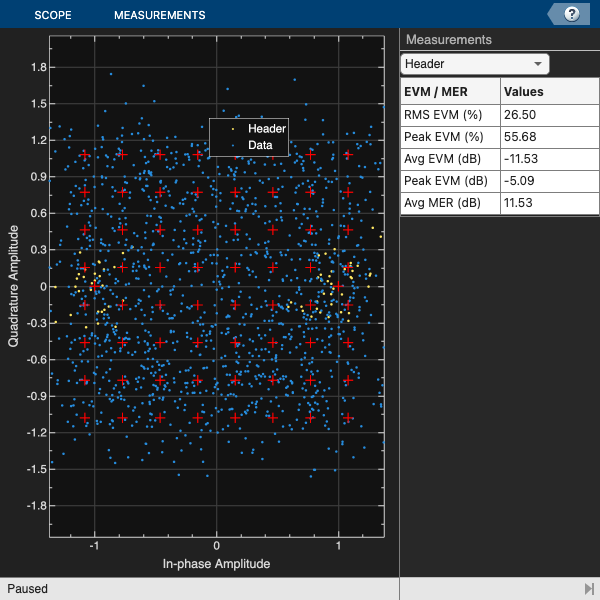

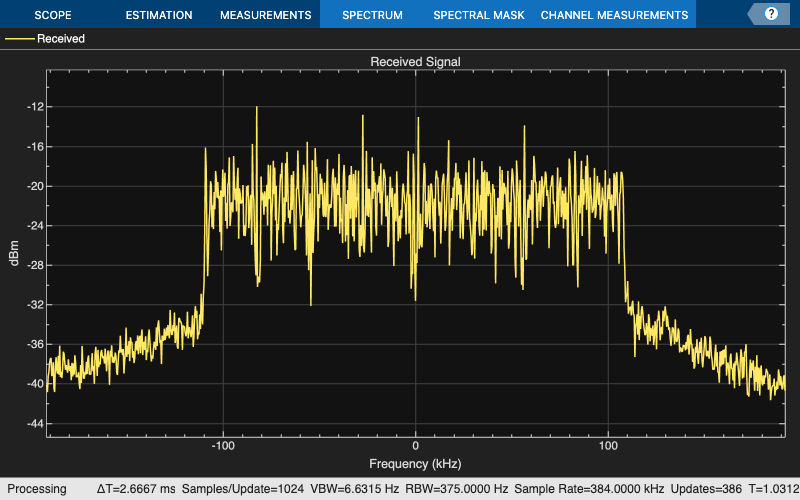

BER = 3.246871e-01 


% Pulizia dell'ambiente e delle variabili
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

%inizializzazione delle variabili e gestione overflow sui frame ricevuti
errorRate = comm.ErrorRate();
toverflow = 0; % Contatore numero di overflow
rxObj = helperOFDMRxInit(sysParam); 
BER = zeros(1,dataParams.numFrames); %memorizzazione valori di BER per ogni frame ricevuto
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio(); %ricezione onda modulata OFDM

    toverflow = toverflow + overflow;

    % Solo se non c'è overflow, passa il segnale al front-end del ricevitore (helperOFDMRxFrontEnd) che  esegue filtraggio e sincronizzazione
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Eseguiamo l'elaborazione del ricevitore
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj); %otteniamo i bit ricevuti, se la connessione è stabile, il tempo di offset di sincronizzazione, dati diagnostici
        sysParam.timingAdvance = toff;

       
        if isConnected %Confronta i bit ricevuti rxDataBits con i dati originali transportBlk per calcolare il BER
            
            % aggiornamento dei valori di BER tramitre comm.ErrorRate
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % Poiché ogni carattere nei dati è codificato da 7 bit, decodifica i dati ricevuti fino agli ultimi multipli di 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        else
            BER(frameNum) = 0.5; %valore standard di BER assegnato in caso di mancata connessione tra i dispositivi 
        end

        %Visualizzazione della costellazione e dello spettro del segnale
        %ricevuto
        if isConnected && dataParams.enableScopes 
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ... 
                 complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
    fprintf('BER = %d \n',BER(frameNum)); %valore di BER ottenuto al ricevitore
end

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))

Simulation complete!
Average BER = 3.182144e-01

### Stima del SNR

%Stima dell'SNR

res = getSpectrumData(spectrumAnalyze); %otteniamo i valori dello spettro del segnale ricevuto
freq = cell2mat(res.FrequencyVector); %vettore delle frequenze dello spettro 
spectrum = cell2mat(res.Spectrum); %vettore della potenza spettrale corrispondente alle frequenze del vettore freq
fmin = -100e3; %frequenza minima
idx = (freq >= fmin) & (freq <= fmin*(-1)); %intervallo di frequenze di interesse
meanPowerdB = mean(spectrum(idx)); %calcolo della potenza media in dB nella banda di interesse (idx)
idx = find(freq == 129000); %Cerco l'indice della frequenza 129 kHz, ipotizzando che sia una frequenza in cui c'è solo rumore (senza segnale utile)
SNRestimation = meanPowerdB - (spectrum(idx)); %detrminiamo l'SNR
SNR_vect = repmat(SNRestimation, 1, dataParams.numFrames); %stima per ogni frame
fprintf('SNR estimated: %d\n', SNRestimation);

SNR estimated: 1.176273e+01


release(radio);
minBer = BER(BER<0.5);
disp(mean(minBer));

    0.3024



% Copyright 2023 The MathWorks, Inc.

## Troubleshooting

#### **No data in any frame**

Problema

Il ricevitore non riceve continuamente dati in nessun frame.

Possibili cause:

-Il trasmettitore non funziona

-Guadagni del trasmettitore e del ricevitore troppo alti o troppo bassi

Troppe sottocorrenti sul trasmettitore

Possibili soluzioni

-Assicurarsi che il trasmettitore funzioni

-Regolare i guadagni del trasmettitore e del ricevitore

-Regolare la lunghezza del frame per assicurarsi che ci siano pochissime sottocorrenti sul trasmettitore.

#### **Header CRC fails**

Problema

Anche quando la sincronizzazione e il campeggio del ricevitore hanno esito positivo, il controllo CRC dell'intestazione fallisce.

Possibili cause:

-Compensazione insufficiente dell'offset della frequenza di clock.

Possibili soluzioni:

-L'algoritmo di compensazione della frequenza misura e corregge l'offset di frequenza e fase per ogni frame e può stimare l'offset corretto fino a metà della spaziatura della sottoportante. È possibile calibrare l'offset di frequenza per risolvere questo errore.

-Per le radio USRP, puoi determinare l'offset di frequenza inviando un tono a una frequenza nota dal trasmettitore e misurando l'offset tra la frequenza trasmessa e quella ricevuta. Applica l'offset misurato alla frequenza centrale dell'oggetto System del ricevitore comm.SDRuReceiver. Per le radio ADALM-Pluto, esegui la calibrazione dell'offset di frequenza con l'esempio ADALM-Pluto Radio in Simulink per ottenere l'offset di frequenza. Applica l'offset misurato alla frequenza centrale dell'oggetto System del ricevitore comm.SDRRxPluto.

#### **Data decoding fails**

Problema

La decodifica dei dati fallisce anche quando la decodifica CRC dell'intestazione ha esito positivo.

Possibili cause:

-Overflow di dati nel ricevitore

-Stima del canale imprecisa a causa del superamento della lunghezza del frame.

Possibili soluzioni:

-Regola la dimensione del frame

-Modifica il numero di simboli per frame per ridurre al minimo la lunghezza del frame.